# LME on acoustic features taking the acoustic category into account

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';

Loading previous data

load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls2.mat'))
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls2.mat'), 'MicAudioGood','CallType',...
    'TAll', 'BatID', 'Duration','RMS_mean','Sal_mean',...
    'F0_mean','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean')
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for Batname
UBat = unique(BatID);
CBat = nan(length(BatID),3);
for bat=1:length(UBat)
    CBat(contains(BatID,UBat(bat)),:) = repmat(ColorCode(bat,:),sum(contains(BatID,UBat(bat))),1);
end

% Get the color vector ready for Sex and Deafness
Path2GGDrive = dir('/Volumes/GoogleDrive*');
Path2RecordingTable = fullfile('/Volumes/', Path2GGDrive.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(length(BatName),1);
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end

end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);

% AcousticClusters = nan(size(Deaf));
% AcousticClusters(strcmp(Deaf, 'D')) = TD;
% AcousticClusters(strcmp(Deaf, 'H')) = T;
AcousticClusters = TAll;

Construct the table of PAF for statistical purposes

Tbl =  table(BatID, CallType, Sex,AcousticClusters,Deaf,log10(Duration),RMS_mean,Sal_mean,F0_mean,Spect_mean,Spect_std,Spect_kurt,Spect_skew,Spect_ent,...
    Time_mean,Time_std,Time_kurt,Time_skew,Time_ent,SpectralMean_mean,Q1_mean,Q2_mean,Q3_mean,SpectMic_mean,SpectMic_std,...
    SpectMic_kurt,SpectMic_skew,SpectMic_ent,Q1Mic_mean,Q2Mic_mean,Q3Mic_mean, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD',...
    'Duration','RMS_mean','Sal_mean','F0_mean','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});
Tbl.AcousticClusters = categorical(Tbl.AcousticClusters);

## Linear mixed-effect models testing for the effect of Sex, Treatment, acoustic cluster and their interactions

The rational here is that we test for the effect of Deaf and its interaction with sex and acoustic cluster by comparing a full LME with an LME with sex and acoustic cluster only as a variable and further test for the interaction if significant by comparing the full LME with the LME omitting the interaction term

Here I am looping through all the acoustic features to apply the same LMEs on all of them 

% List of variables
AcVars = Tbl.Properties.VariableNames(6:end);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix = nan(length(AcVars),4);



for vv=1:length(AcVars)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    if contains(AcVars{vv}, 'Mic')
        Tbl_local = table(BatID(MicAudioGood01), CallType(MicAudioGood01), Sex(MicAudioGood01),AcousticClusters(MicAudioGood01),Deaf(MicAudioGood01), AcVar(MicAudioGood01), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
    else
        Tbl_local = table(BatID, CallType, Sex,AcousticClusters,Deaf, AcVar, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
    end
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
    Tbl_local.AcousticClusters = categorical(Tbl_local.AcousticClusters);

    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD * AcousticClusters+ (AcousticClusters|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ Sex * AcousticClusters + (AcousticClusters|BatID)');
    TestLME_HD=compare(lmeR, lme)

    Pvalue_matrix(vv,1) = TestLME_HD.pValue(2);
    if TestLME_HD.pValue(2)<0.05
        lme
        lme2 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + HorD * AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int3=compare(lme2, lme)
        Pvalue_matrix(vv,2) = TestLME_Int3.pValue(2);
        lme3 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int_HorD_AcCluster=compare(lme3, lme2)
        Pvalue_matrix(vv,3) = TestLME_Int_HorD_AcCluster.pValue(2);
        lme4 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD * AcousticClusters + (AcousticClusters|BatID)');
        TestLME_Int_HorD_Sex=compare(lme4, lme2)
        Pvalue_matrix(vv,4) = TestLME_Int_HorD_Sex.pValue(2);
    end
end

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Duration   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     64    25527    26010    -12699                                 
    lme      82    25535    26154    -12686    27.415    18         0.071533


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lmeR     64    -33152    -32670    16640                                   
    lme      82    -33153    -32535    16659     37.126    18         0.0050458


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13937
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -33153    -32535    16659            -33317  

Fixed effects coefficients (95% CIs):
    Name                                       Estimate      SE           tStat       DF       pValue        Lower         Upper    
    {'(Intercept)'                    }          0.089299     0.010123      8.8216    13901    1.2609e-18      0.069457      0.10914
    {'Sex_M'                          }          0.039223     0.015817      2.4797    13901      0.013159    

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue    
    lme2     66    -33144    -32646    16638                                    
    lme      82    -33153    -32535    16659     41.39     16         0.00048621


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme3     58    -33153    -32716    16635                                 
    lme2     66    -33144    -32646    16638     6.9464    8          0.54242


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lme4     65    -33145    -32655    16638                                  
    lme2     66    -33144    -32646    16638     0.52411    1          0.46909


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Sal_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     64    -6882.9      -6403    3505.4                                  
    lme      82    -6884.3    -6269.5    3524.2    37.436    18         0.0045966


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13334
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6884.3    -6269.5    3524.2           -7048.3 

Fixed effects coefficients (95% CIs):
    Name                                       Estimate      SE          tStat       DF       pValue        Lower        Upper     
    {'(Intercept)'                    }            0.3715    0.032715      11.356    13298    9.5107e-30      0.30738       0.43563
    {'Sex_M'                          }          0.088835    0.051256      1.7331    13298      0.083093   

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lme2     66    -6891.6    -6396.7    3511.8                                 
    lme      82    -6884.3    -6269.5    3524.2    24.707    16         0.075154


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lme3     58    -6895.5    -6460.6    3505.7                                
    lme2     66    -6891.6    -6396.7    3511.8    12.122    8          0.14585


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat       deltaDF    pValue 
    lme4     65    -6893.6    -6406.2    3511.8                                   
    lme2     66    -6891.6    -6396.7    3511.8    0.0045049    1          0.94649


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on F0_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     64    1.8377e+05    1.8424e+05    -91821                                
    lme      82    1.8378e+05    1.8439e+05    -91810    20.842    18         0.28744


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lmeR     64    2.0808e+05    2.0856e+05    -1.0397e+05                                 
    lme      82    2.0808e+05     2.087e+05    -1.0396e+05    26.723    18         0.084336


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_std   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue  
    lmeR     64    1.9523e+05    1.9571e+05    -97552                                 
    lme      82    1.9523e+05    1.9585e+05    -97534    35.077    18         0.009244


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13937
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.9523e+05    1.9585e+05    -97534           1.9507e+05

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF       pValue        Lower      Upper  
    {'(Intercept)'                    }         906.08     67.122       13.499    13901    2.8864e-41     774.51     1037.6
    {'Sex_M'                          }         55.186     105.75      0.52187    13901       0.60177    -1

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue  
    lme2     66    1.9523e+05    1.9572e+05    -97547                                 
    lme      82    1.9523e+05    1.9585e+05    -97534    26.812    16         0.043625


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue
    lme3     58    1.9522e+05    1.9566e+05    -97553                               
    lme2     66    1.9523e+05    1.9572e+05    -97547    11.066    8          0.198 


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lme4     65    1.9523e+05    1.9572e+05    -97548                                
    lme2     66    1.9523e+05    1.9572e+05    -97547    0.2716    1          0.60226


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     64    1.3048e+05    1.3096e+05    -65175                                
    lme      82    1.3049e+05    1.3111e+05    -65165    20.447    18         0.30821


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_skew   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     64    50276    50759    -25074                                
    lme      82    50288    50906    -25062    24.509    18         0.13906


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Spect_ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lmeR     64    -25057    -24575    12593                                   
    lme      82    -25062    -24444    12613     40.964    18         0.0015398


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13937
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -25062    -24444    12613            -25226  

Fixed effects coefficients (95% CIs):
    Name                                       Estimate      SE           tStat        DF       pValue         Lower         Upper    
    {'(Intercept)'                    }           0.71613     0.018727        38.24    13901    2.6489e-304       0.67942      0.75284
    {'Sex_M'                          }         -0.020862     0.029425       -0.709    13901        0.478

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lme2     66    -25066    -24568    12599                                  
    lme      82    -25062    -24444    12613     28.803    16         0.025299


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme3     58    -25069    -24631    12592                                 
    lme2     66    -25066    -24568    12599     13.039    8          0.11052


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lme4     65    -25062    -24572    12596                                  
    lme2     66    -25066    -24568    12599     5.3229    1          0.021046


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lmeR     64    -17884    -17401    9005.8                                 
    lme      82    -17878    -17260      9021    30.432    18         0.033449


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13937
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -17878    -17260    9021             -18042  

Fixed effects coefficients (95% CIs):
    Name                                       Estimate      SE           tStat        DF       pValue        Lower         Upper     
    {'(Intercept)'                    }          0.057677     0.010232       5.6367    13901     1.767e-08       0.03762      0.077734
    {'Sex_M'                          }          0.001913     0.015538      0.12312    13901       0.9020

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lme2     66    -17886    -17388    9009.1                                 
    lme      82    -17878    -17260      9021    23.764    16         0.094781


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue
    lme3     58    -17892    -17455    9004.2                               
    lme2     66    -17886    -17388    9009.1    9.9184    8          0.2708


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat       deltaDF    pValue 
    lme4     65    -17888    -17398    9009.1                                   
    lme2     66    -17886    -17388    9009.1    0.0021825    1          0.96274


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_std   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     64    -33235    -32752    16682                                 
    lme      82    -33225    -32606    16694     25.492    18         0.11194


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     64    34966    35449    -17419                                
    lme      82    34981    35599    -17408    21.593    18         0.25054


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_skew   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     64    16469    16952    -8170.4                                 
    lme      82    16477    17096    -8156.6    27.776    18         0.065549


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Time_ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lmeR     64    -51406    -50923    25767                                   
    lme      82    -51408    -50789    25786     37.686    18         0.0042611


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13937
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -51408    -50789    25786            -51572  

Fixed effects coefficients (95% CIs):
    Name                                       Estimate       SE           tStat        DF       pValue       Lower          Upper      
    {'(Intercept)'                    }            0.93128    0.0063494       146.67    13901            0        0.91884        0.94373
    {'Sex_M'                          }          0.0001723    0.0099566     0.017305    13901      0.

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lme2     66    -51408    -50910    25770                                  
    lme      82    -51408    -50789    25786     31.915    16         0.010258


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme3     58    -51418    -50980    25767                                 
    lme2     66    -51408    -50910    25770     6.1258    8          0.63315


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lme4     65    -51402    -50912    25766                                  
    lme2     66    -51408    -50910    25770     7.7609    1          0.005339


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectralMean_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik         LRStat    deltaDF    pValue  
    lmeR     64    2.146e+05    2.1508e+05    -1.0723e+05                                 
    lme      82    2.146e+05    2.1522e+05    -1.0722e+05    30.092    18         0.036565


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13933
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    2.146e+05    2.1522e+05    -1.0722e+05      2.1444e+05

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF       pValue         Lower      Upper  
    {'(Intercept)'                    }         3692.9      111.6       33.09    13897    3.4043e-231     3474.1     3911.7
    {'Sex_M'                          }         398.24     175.57      2.2683    13897       0.023324     54.

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue
    lme2     66    2.1459e+05    2.1509e+05    -1.0723e+05                               
    lme      82     2.146e+05    2.1522e+05    -1.0722e+05    18.009    16         0.3234


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lme3     58    2.1459e+05    2.1502e+05    -1.0724e+05                                 
    lme2     66    2.1459e+05    2.1509e+05    -1.0723e+05    13.574    8          0.093573


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue   
    lme4     65    2.1459e+05    2.1508e+05    -1.0723e+05                                  
    lme2     66    2.1459e+05    2.1509e+05    -1.0723e+05    6.86      1          0.0088149


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue  
    lmeR     64     1.949e+05    1.9538e+05    -97386                                 
    lme      82    1.9491e+05    1.9553e+05    -97373    27.063    18         0.077819


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q2_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lmeR     64    2.1487e+05    2.1535e+05    -1.0737e+05                                 
    lme      82    2.1488e+05     2.155e+05    -1.0736e+05    26.231    18         0.094593


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q3_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lmeR     64    2.2973e+05    2.3021e+05     -1.148e+05                                 
    lme      82    2.2973e+05    2.3035e+05    -1.1478e+05    29.893    18         0.038504


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           13933
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    2.2973e+05    2.3035e+05    -1.1478e+05      2.2957e+05

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF       pValue         Lower      Upper  
    {'(Intercept)'                    }         5499.5      196.5      27.988    13897    9.8557e-168     5114.4     5884.7
    {'Sex_M'                          }          676.5     309.22      2.1878    13897       0.028702     7

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue
    lme2     66    2.2972e+05    2.3022e+05    -1.1479e+05                               
    lme      82    2.2973e+05    2.3035e+05    -1.1478e+05    18.216    16         0.3114


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lme3     58    2.2972e+05    2.3015e+05     -1.148e+05                                 
    lme2     66    2.2972e+05    2.3022e+05    -1.1479e+05    13.964    8          0.082696


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lme4     65    2.2972e+05    2.3021e+05    -1.1479e+05                                 
    lme2     66    2.2972e+05    2.3022e+05    -1.1479e+05    4.0865    1          0.043228


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue  
    lmeR     64    1.5919e+05    1.5964e+05    -79530                                 
    lme      82     1.592e+05    1.5978e+05    -79516    27.105    18         0.077052


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_std   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue  
    lmeR     64    1.5284e+05     1.533e+05    -76358                                 
    lme      82    1.5285e+05    1.5343e+05    -76341    33.751    18         0.013517


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            8632
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.5285e+05    1.5343e+05    -76341           1.5268e+05

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF      pValue        Lower      Upper  
    {'(Intercept)'                    }         4207.5      200.1       21.027    8596    9.2988e-96     3815.3     4599.8
    {'Sex_M'                          }        -987.02     304.18      -3.2449    8596     0.0011796    -1583

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue   
    lme2     66    1.5285e+05    1.5332e+05    -76361                                  
    lme      82    1.5285e+05    1.5343e+05    -76341    39.247    16         0.0010019


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lme3     58    1.5284e+05    1.5325e+05    -76364                                
    lme2     66    1.5285e+05    1.5332e+05    -76361    7.6497    8          0.46841


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue   
    lme4     65    1.5286e+05    1.5332e+05    -76365                                  
    lme2     66    1.5285e+05    1.5332e+05    -76361    8.0264    1          0.0046102


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_kurt   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue  
    lmeR     64    1.0649e+05    1.0694e+05    -53179                                 
    lme      82    1.0649e+05    1.0707e+05    -53164    29.705    18         0.040417


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            8632
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.0649e+05    1.0707e+05    -53164           1.0633e+05

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat       DF      pValue        Lower      Upper  
    {'(Intercept)'                    }         44.186     11.588      3.8132    8596    0.00013813     21.471       66.9
    {'Sex_M'                          }         85.026     17.331      4.9061    8596    9.4627e-07     51.053 

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue   
    lme2     66     1.065e+05    1.0696e+05    -53182                                  
    lme      82    1.0649e+05    1.0707e+05    -53164    36.511    16         0.0024562


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lme3     58    1.0649e+05     1.069e+05    -53187                                
    lme2     66     1.065e+05    1.0696e+05    -53182    9.513     8          0.30088


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat    deltaDF    pValue  
    lme4     65    1.065e+05    1.0696e+05    -53184                                 
    lme2     66    1.065e+05    1.0696e+05    -53182    4.3074    1          0.037948


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_skew   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     64    49081    49533    -24476                                 
    lme      82    49083    49662    -24459    33.929    18         0.012852


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            8632
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    49083    49662    -24459           48919   

Fixed effects coefficients (95% CIs):
    Name                                       Estimate     SE         tStat       DF      pValue        Lower       Upper   
    {'(Intercept)'                    }           4.5432    0.67307      6.7499    8596    1.5748e-11      3.2238      5.8626
    {'Sex_M'                          }            3.448     1.0428      3.3065    8596    0.00094864      1.4039      5.4922
 

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme2     66    49088    49554    -24478                                  
    lme      82    49083    49662    -24459    36.841    16         0.0022075


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme3     58    49085    49494    -24484                                
    lme2     66    49088    49554    -24478    13.047    8          0.11024


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lme4     65    49090    49549    -24480                                 
    lme2     66    49088    49554    -24478    4.6168    1          0.031661


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on SpectMic_ent   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lmeR     64    -11963    -11511    6045.5                                  
    lme      82    -11963    -11384    6063.4    35.803    18         0.0074778


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            8632
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -11963    -11384    6063.4           -12127  

Fixed effects coefficients (95% CIs):
    Name                                       Estimate       SE          tStat        DF      pValue         Lower         Upper    
    {'(Intercept)'                    }             0.5881     0.02562       22.955    8596    3.1845e-113       0.53788      0.63832
    {'Sex_M'                          }           -0.09293    0.040037      -2.3211    8596       0.020306 

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lme2     66    -11960    -11494    6046.2                                  
    lme      82    -11963    -11384    6063.4    34.407    16         0.0047863


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme3     58    -11965    -11555    6040.4                                
    lme2     66    -11960    -11494    6046.2    11.53     8          0.17343


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lme4     65    -11958    -11499    6043.9                                 
    lme2     66    -11960    -11494    6046.2    4.5803    1          0.032341


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q1Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat    deltaDF    pValue   
    lmeR     64    1.571e+05    1.5755e+05    -78487                                  
    lme      82    1.571e+05    1.5768e+05    -78470    35.467    18         0.0082506


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            8627
    Fixed effects coefficients          36
    Random effects coefficients         90
    Covariance parameters               46

Formula:
    AcVar ~ 1 + Sex*AcousticClusters + Sex*HorD + AcousticClusters*HorD + Sex:AcousticClusters:HorD + (1 + AcousticClusters | BatID)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    1.571e+05    1.5768e+05    -78470           1.5694e+05

Fixed effects coefficients (95% CIs):
    Name                                       Estimate    SE        tStat        DF      pValue        Lower      Upper  
    {'(Intercept)'                    }         4867.6     409.01       11.901    8591    2.0999e-32     4065.8     5669.3
    {'Sex_M'                          }        -161.27     636.93      -0.2532    8591       0.80012    -1409.8

TestLME_Int3 =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat    deltaDF    pValue  
    lme2     66    1.571e+05    1.5757e+05    -78485                                 
    lme      82    1.571e+05    1.5768e+05    -78470    30.325    16         0.016389


TestLME_Int_HorD_AcCluster =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat    deltaDF    pValue  
    lme3     58    1.571e+05    1.5751e+05    -78492                                 
    lme2     66    1.571e+05    1.5757e+05    -78485    13.367    8          0.099835


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue    
    lme4     65    1.5711e+05    1.5757e+05    -78491                                   
    lme2     66     1.571e+05    1.5757e+05    -78485    11.559    1          0.00067438


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q2Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     64    1.7136e+05    1.7181e+05    -85617                                
    lme      82    1.7137e+05    1.7195e+05    -85605    23.428    18         0.17468


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on Q3Mic_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     64     1.812e+05    1.8166e+05    -90538                                
    lme      82    1.8122e+05     1.818e+05    -90529    19.848    18         0.34145


**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

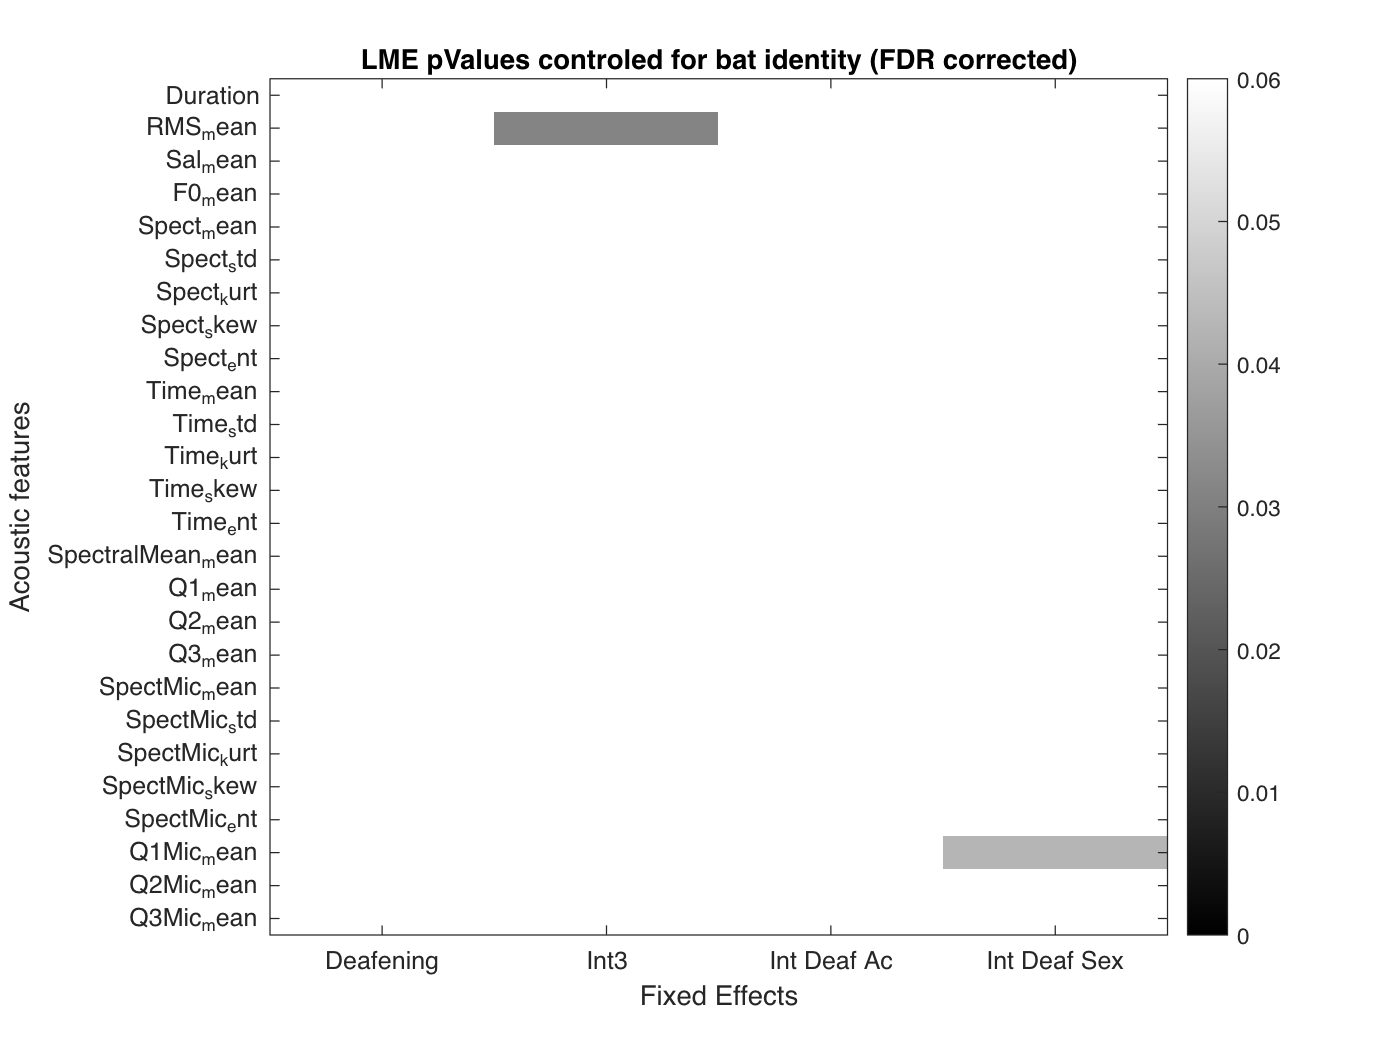

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = [Pvalue_matrix(:,1);Pvalue_matrix(:,2);Pvalue_matrix(:,3);Pvalue_matrix(:,4)];
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrixFDR = [Pvalue_vectorFDR(1:size(Pvalue_matrix,1)) Pvalue_vectorFDR((size(Pvalue_matrix,1)+1) : 2*size(Pvalue_matrix,1)) Pvalue_vectorFDR((2*size(Pvalue_matrix,1)+1) : 3*size(Pvalue_matrix,1)) Pvalue_vectorFDR((3*size(Pvalue_matrix,1)+1) : end)];
% Pvalue_matrix4plot = Pvalue_matrix;
% Pvalue_matrix4plot(isnan(Pvalue_matrix))=1;

figure()
% tiledlayout(1,2)
% nexttile
% Im = imagesc(Pvalue_matrix4plot);
% colorbar()
% colormap(Im.Parent,'gray')
% Im.Parent.CLim = [0 0.06];
% set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
% set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
% ylabel('Acoustic features')
% xlabel('Fixed Effects')
% title('LME pValues controled for bat identity')
% nexttile
Im = imagesc(Pvalue_matrixFDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues controled for bat identity (FDR corrected)')

save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls2.mat'),'Pvalue_matrixFDR','AcVars', '-append')

## Now let's do post-hoc LME to investigate the effect of Deafening in each acoustical category for each significant feature

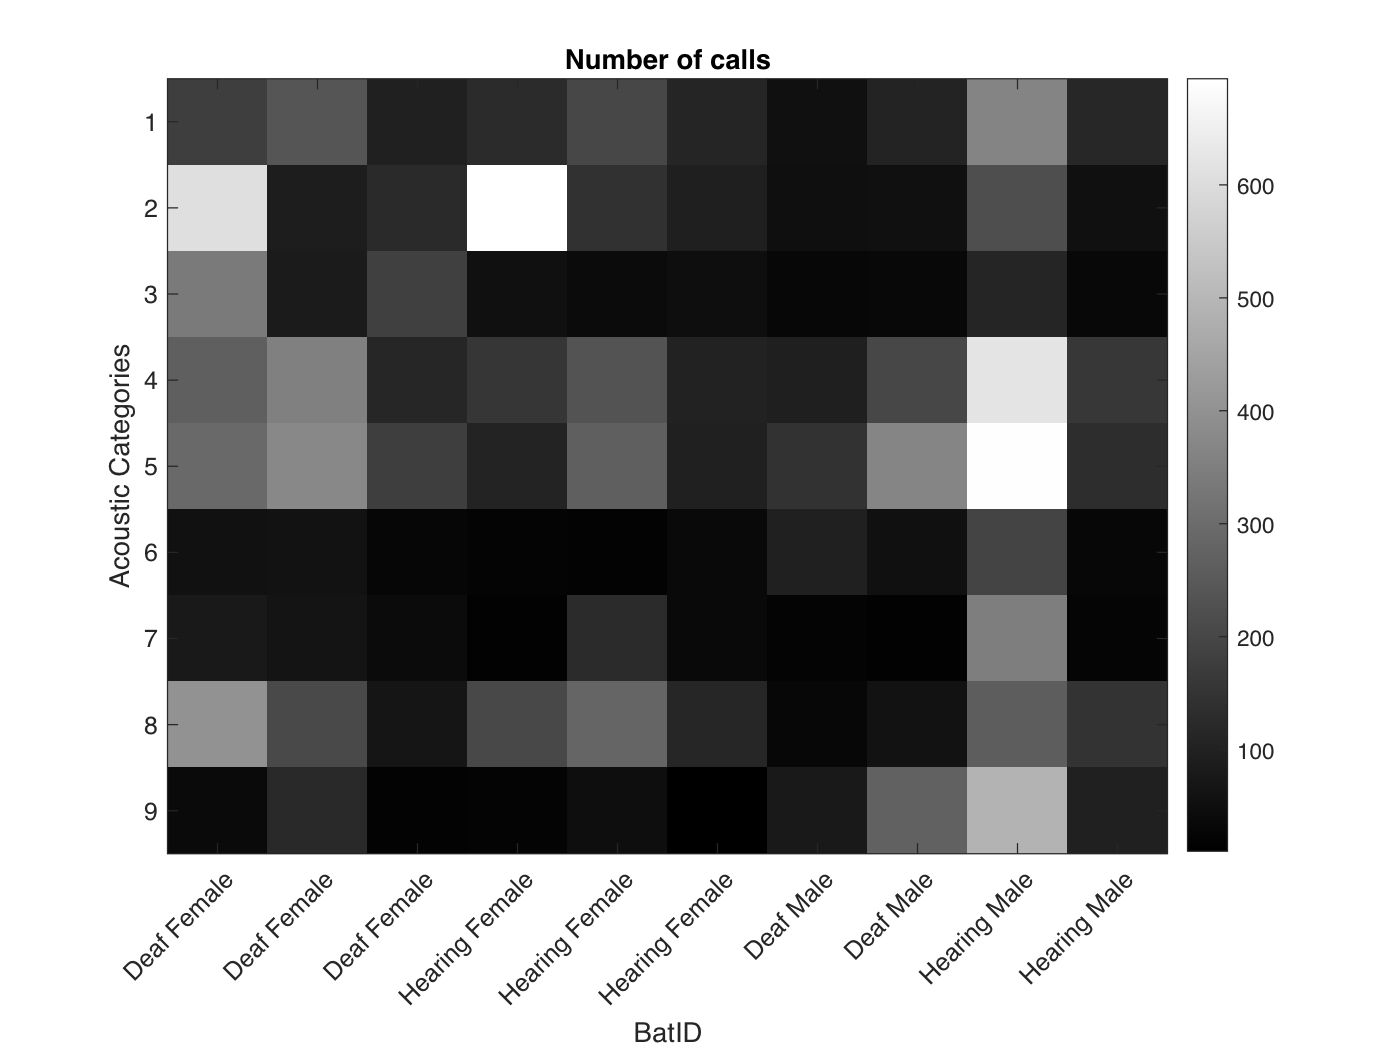

UCat = unique(AcousticClusters);
NumCalls = nan(length(UCat), length(BatName));
PCalls = nan(length(UCat), length(BatName));
for bb=1:length(BatName)
    for cc=1:length(UCat)
        NumCalls(cc,bb) = sum((AcousticClusters==UCat(cc)).* strcmp(BatID, num2str(BatName(bb))));
    end
    PCalls(:,bb) = NumCalls(:,bb)./sum(NumCalls(:,bb));
end
figure()
IM = imagesc(NumCalls);
xlabel('BatID')
ylabel('Acoustic Categories')
colorbar()
colormap("gray")
title('Number of calls')
IM.Parent.XTick = 1:length(BatName);
IM.Parent.XTickLabels=BatSexDeaf;
IM.Parent.XTickLabelRotation = 45;

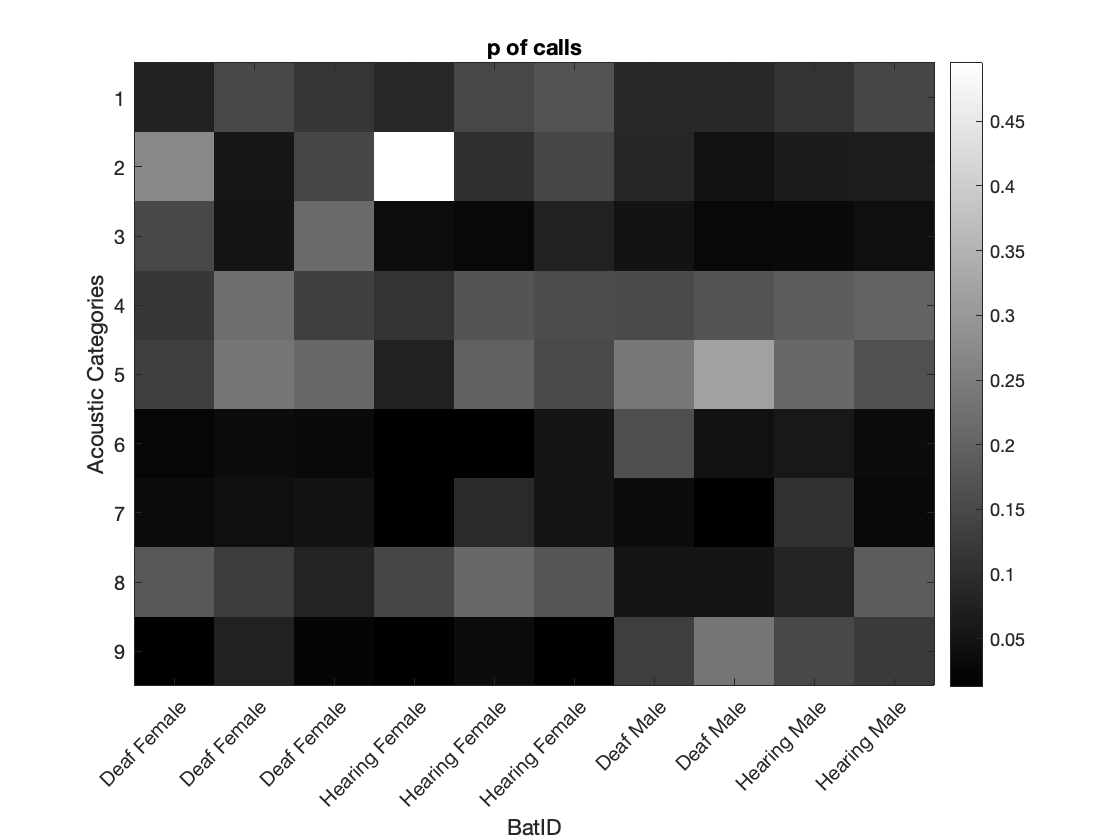

figure()
IM = imagesc(PCalls);
xlabel('BatID')
ylabel('Acoustic Categories')
colorbar()
colormap("gray")
title('p of calls')
IM.Parent.XTick = 1:length(BatName);
IM.Parent.XTickLabels=BatSexDeaf;
IM.Parent.XTickLabelRotation = 45;

Note that for categories 6,7 and 9 females have emitted very few of these calls -> we should probably only focus on males for these categories

Go through all acoustic categories and run an LME testing for the effect of Sex and deafening controling for BatID. Make sure that there are enough points per model for each sub-category!

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lmeR     4     -4293.6    -4272.1    2150.8                               
    lme      6       -4291    -4258.8    2151.5    1.4763    2          0.478 


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     4     -6146.5    -6123.9    3077.3                                  
    lme      6     -6153.6    -6119.6    3082.8    11.046    2          0.0039946


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue    
    lme2     5     -6136.3      -6108    3073.2                                   
    lme      6     -6153.6    -6119.6    3082.8    19.273    1          1.1328e-05


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2129
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6153.6    -6119.6    3082.8           -6165.6 

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE           tStat      DF      pValue         Lower        Upper    
    {'(Intercept)' }          0.15621    0.0034358     45.465    2125    7.6326e-316      0.14947      0.16295
    {'Sex_F'       }        -0.065571    0.0039098    -16.771    2125     2.2088e-59    -0.073238    -0.057904
    {'HorD_D'      }        -0.010972    0.0064834    -1.6923    2125       0.090732    -0.023686    0.0017425
    {'Sex_F:HorD_D'} 

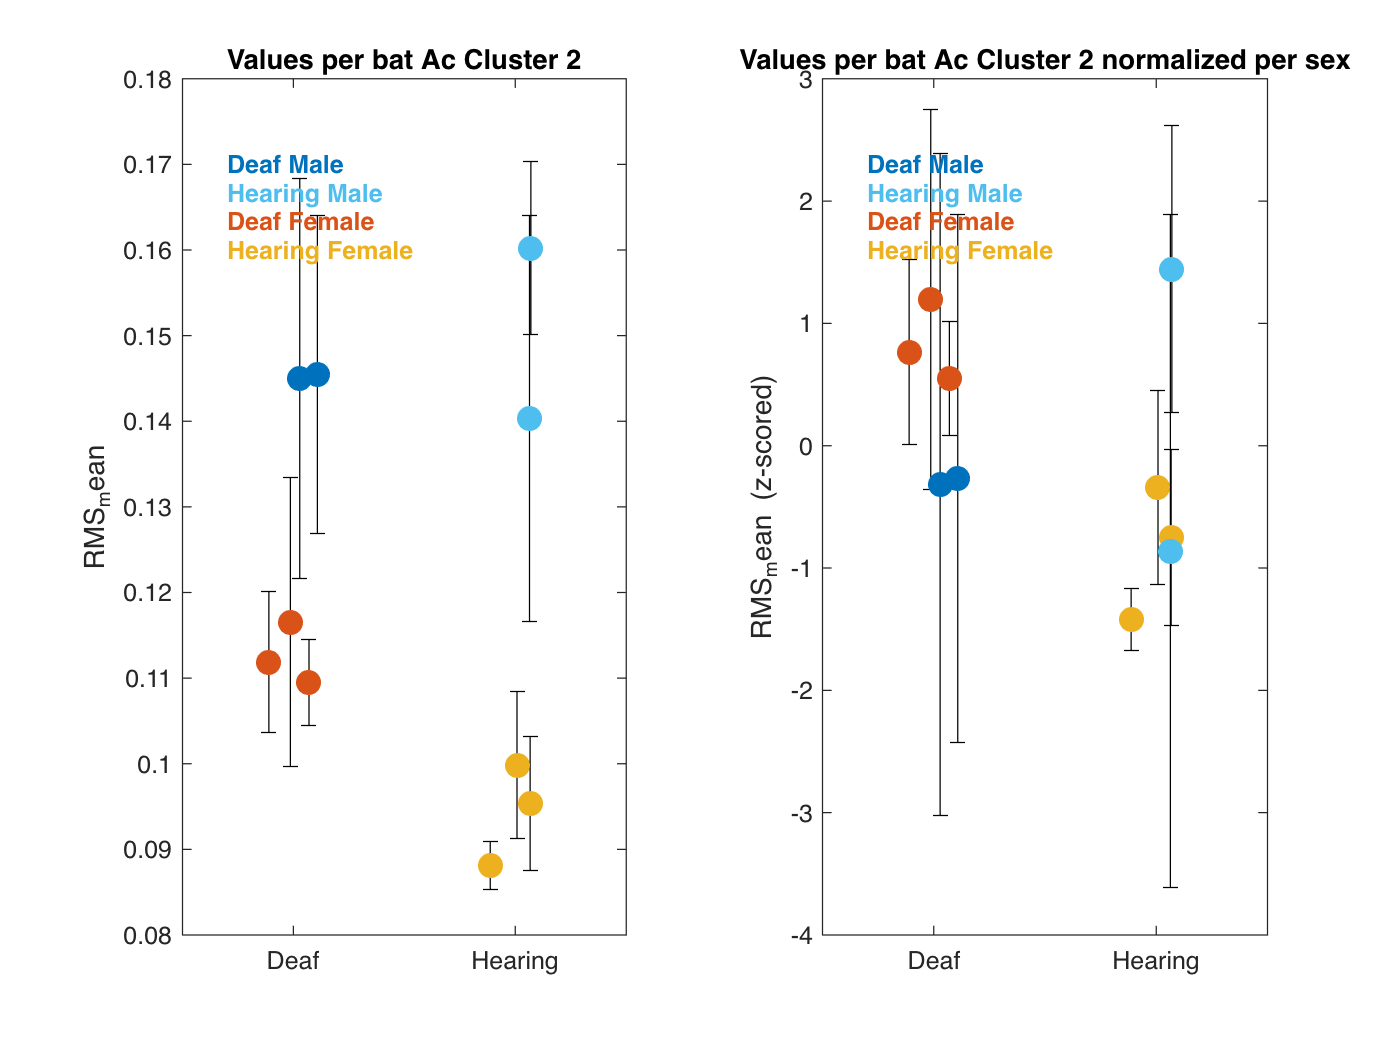

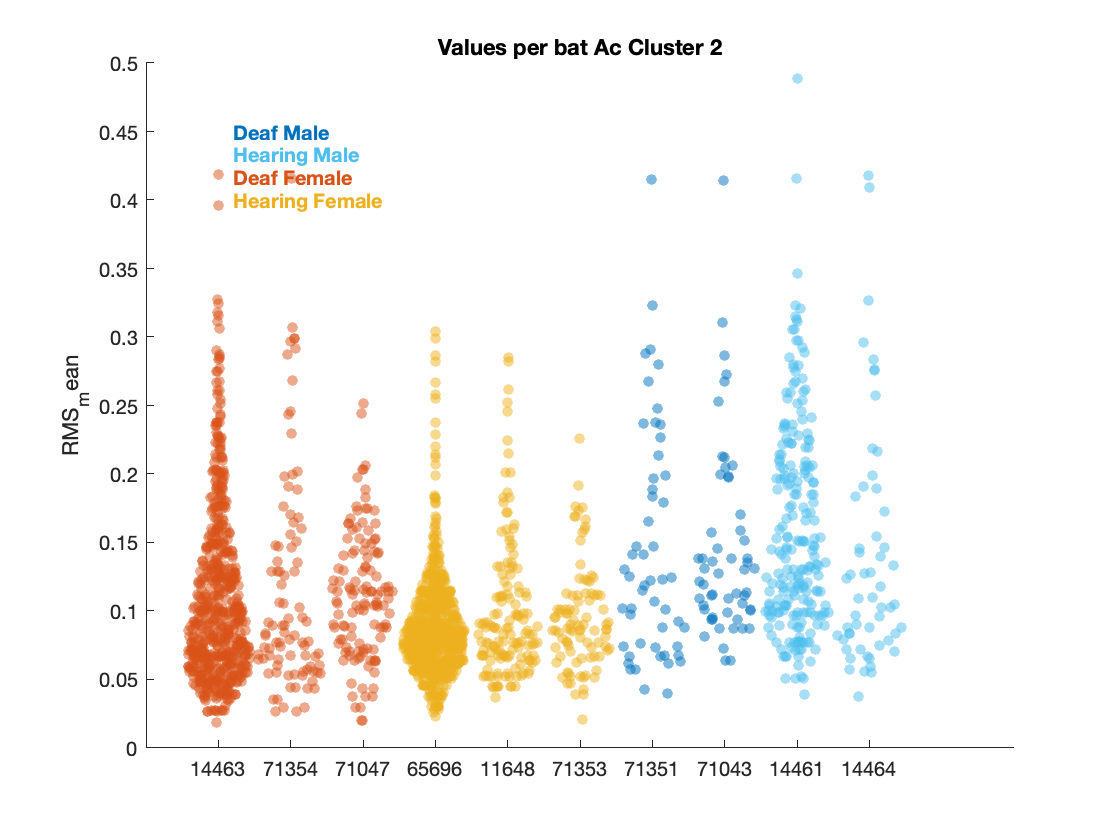

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue
    lmeR     4       -2470    -2450.6      1239                               
    lme      6     -2451.6    -2422.4    1231.8    -14.39    2          1     


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     4     -5312.1    -5289.1      2660                                 
    lme      6     -5308.9    -5274.4    2660.4    0.79594    2          0.67168


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     4       -5746    -5722.4      2877                                
    lme      6     -5744.2    -5708.9    2878.1    2.1917    2          0.33425


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue    
    lmeR     4       -1226    -1208.4    616.99                                   
    lme      6     -1238.4    -1212.2    625.22    16.467    2          0.00026557


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue    
    lme2     5     -1229.1    -1207.2    619.56                                   
    lme      6     -1238.4    -1212.2    625.22    11.321    1          0.00076633


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             591
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -1238.4    -1212.2    625.22           -1250.4 

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE           tStat      DF     pValue        Lower        Upper    
    {'(Intercept)' }          0.20563     0.005651     36.388    587    1.372e-152      0.19453      0.21673
    {'Sex_F'       }        -0.081106     0.011117    -7.2957    587    9.6839e-13     -0.10294    -0.059272
    {'HorD_D'      }         0.061875    0.0088697     6.9761    587    8.2156e-12     0.044455     0.079296
    {'Sex_F:HorD_D'}        -

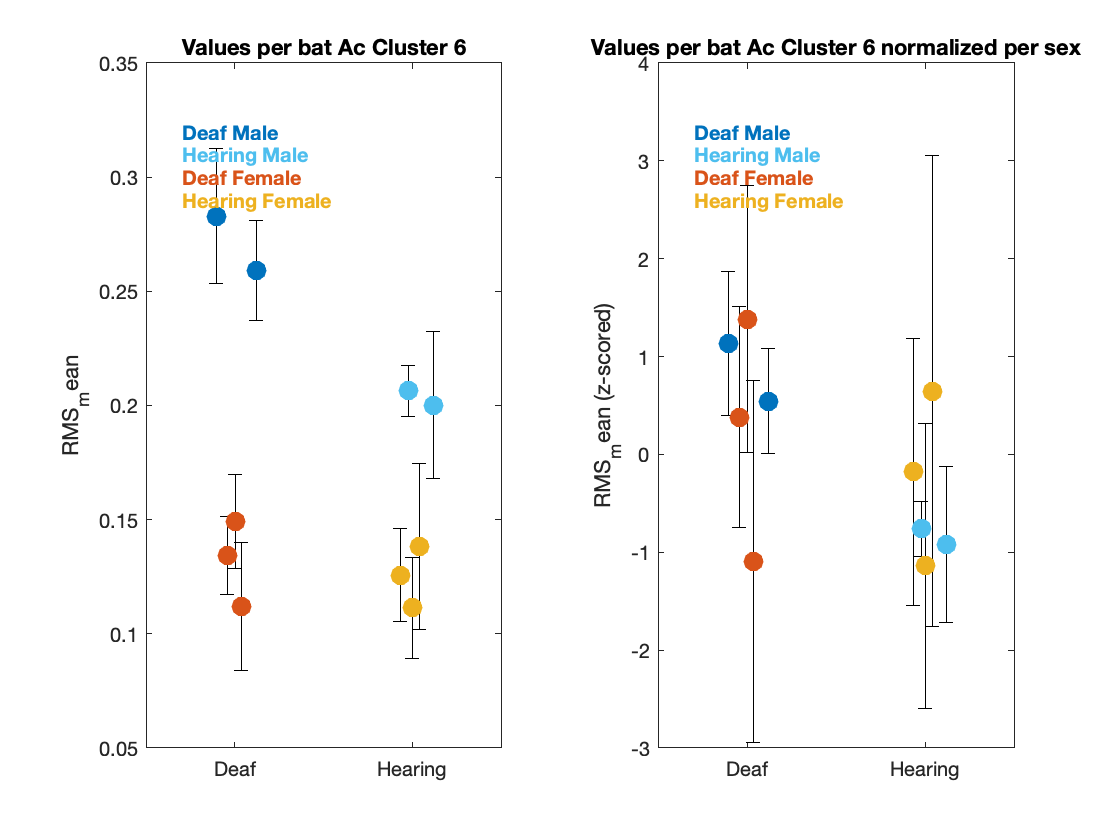

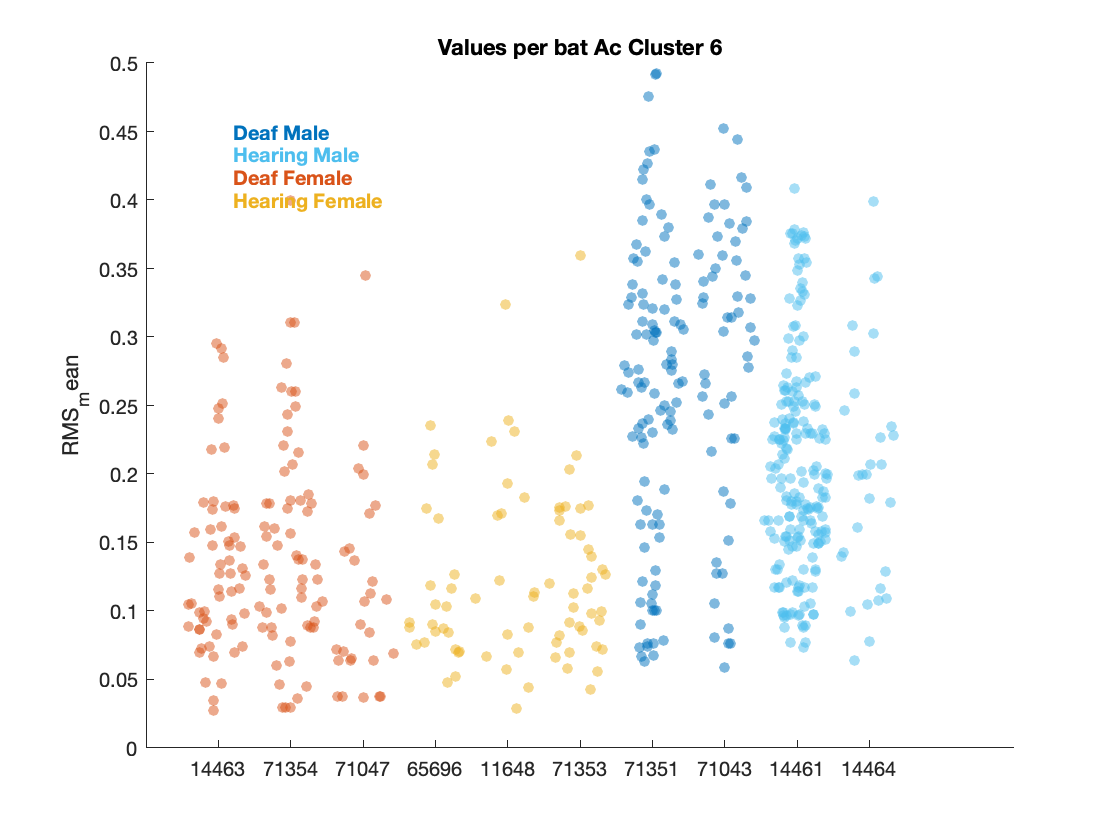

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 7----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -1697.5    -1678.9    852.77                                
    lme      6     -1694.9      -1667    853.47    1.3966    2          0.49744


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 8----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -5556.8    -5534.9    2782.4                                
    lme      6     -5554.4    -5521.5    2783.2    1.6452    2          0.43929


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 9----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -1932.3      -1912    970.17                                
    lme      6     -1931.9    -1901.4    971.94    3.5565    2          0.16893


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


% List of variables that were significant at the previous stage analysis
SigAcVars = logical((Pvalue_matrixFDR(:,1)<0.05) + ((Pvalue_matrixFDR(:,2)<0.05) + (Pvalue_matrixFDR(:,3)<0.05)));
AcVars = Tbl.Properties.VariableNames(6:end);
AcVars = AcVars(SigAcVars);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix_Post_hoc = nan(length(AcVars),2,length(UCat));


for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    for vv=1:length(AcVars)
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
        AcVar = Tbl.(sprintf('%s',AcVars{vv}));
        if contains(AcVars{vv}, 'Mic')
            Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)));
            Tbl_local = table(BatID(Ind), CallType(Ind), Sex(Ind),AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        else
            Ind = AcousticClusters==UCat(cc);
            Tbl_local = table(BatID(Ind), CallType(Ind), Sex(Ind),AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        end
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

        % Full Model
        lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + (1|BatID)');
        % Reduced model without deafening fixed effect
        lmeR = fitlme(Tbl_local, 'AcVar ~ Sex + (1|BatID)');
        TestLME_HD=compare(lmeR, lme)

        Pvalue_matrix_Post_hoc(vv,1,cc) = TestLME_HD.pValue(2);
        if TestLME_HD.pValue(2)<0.05
            lme2 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD + (1|BatID)');
            TestLME_Int_HorD_Sex=compare(lme2, lme)
            Pvalue_matrix_Post_hoc(vv,2,cc) = TestLME_Int_HorD_Sex.pValue(2);
            lme

            % Nice plot 1
            AcVar_mean_pBat = nan(size(BatName));
            AcVar_se_pBat = nan(size(BatName));
            Col_local = nan(length(BatName),3);
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
                AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
            end

            AcVar_Male_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
            AcVar_Male_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
            AcVar_Female_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
            AcVar_Female_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
            AcVar_meanse_pBat_sexnorm = nan(length(AcVar_mean_pBat),2);
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                if contains(BatSexDeaf{bb}, 'Male')
                    AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan');
                    AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                elseif contains(BatSexDeaf{bb}, 'Female')
                    AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan');
                    AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                end
            end
            figure()
            tiledlayout(1,2)
            nexttile
            XHorD = ones(size(BatSexDeaf)) + (rand(size(BatSexDeaf))-0.5).*0.5;
            XHorD(contains(BatSexDeaf, 'Hearing')) = XHorD(contains(BatSexDeaf, 'Hearing'))+2;

            errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.')
            hold on
            scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
            ylabel(sprintf('%s', AcVars{vv}))
            XLim = [0 4];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d', UCat(cc)))

            nexttile
            errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
            hold on
            scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
            ylabel(sprintf('%s (z-scored)', AcVars{vv}))
            XLim = [0 4];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))

            % Nice plot 2
            figure()
            for bb=1:length(BatName)
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                hold on
                swarmchart(bb*ones(sum(Ind),1),AcVar(Ind),30,Col_local(bb,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            end
            hold on
            ylabel(sprintf('%s', AcVars{vv}));
            YLim = get(gca, 'YLim');
            XLim = get(gca, 'XLim');
            for ct=1:length(USexDeaf)
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', 1:length(BatSexDeaf),'XTickLabel', BatName)
            hold off
            title(sprintf('Values per bat Ac Cluster %d', UCat(cc)))

        end
    end
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
end

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

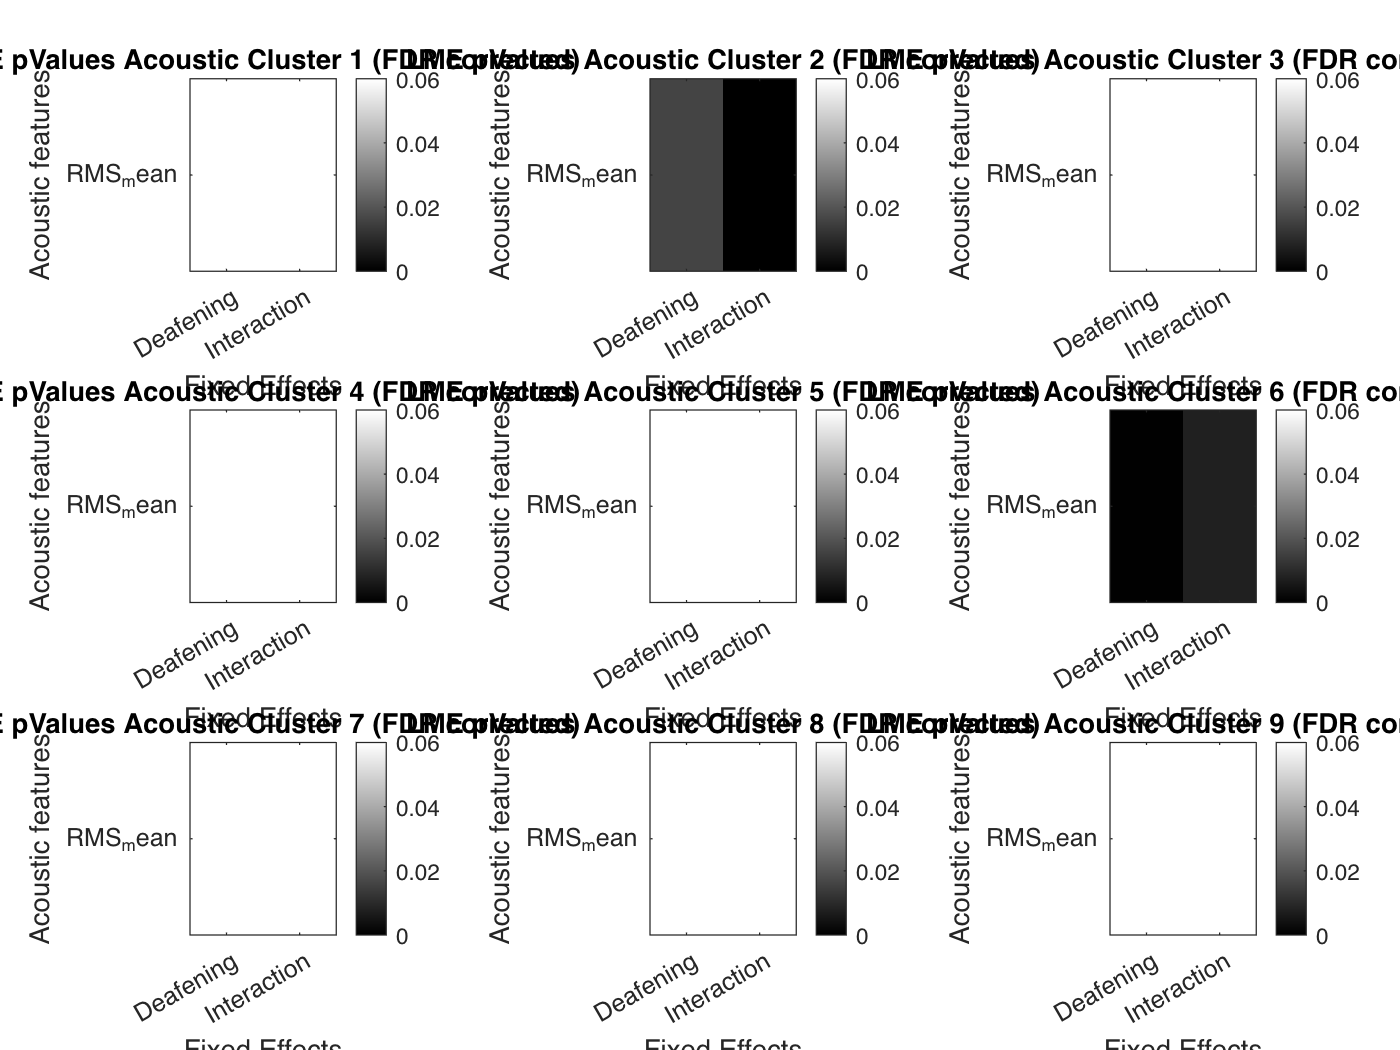

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = cell(1,length(UCat));
for cc=1:length(UCat)
    Pvalue_vector{cc} = [Pvalue_matrix_Post_hoc(:,1,cc)' Pvalue_matrix_Post_hoc(:,2,cc)'];
end
Pvalue_vector = [Pvalue_vector{:}];
NonNaNInd = ~isnan(Pvalue_vector);
[~,Ord]=sort(Pvalue_vector(NonNaNInd));
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);

Pvalue_matrix_Post_hocFDR = nan(size(Pvalue_matrix_Post_hoc));
NVars = size(Pvalue_matrix_Post_hoc,1);
for cc=1:length(UCat)
    Pvalue_matrix_Post_hocFDR(:,:,cc) = [Pvalue_vectorFDR(((cc-1)*2*NVars) + (1:NVars))' Pvalue_vectorFDR(((cc-1)*2*NVars) + ((NVars+1):2*NVars))'];
end

figure()
tiledlayout(3,3)
for cc=1:length(UCat)
    nexttile
    Im = imagesc(Pvalue_matrix_Post_hocFDR(:,:,cc));
    colorbar()
    colormap(Im.Parent,'gray')
    Im.Parent.CLim = [0 0.06];
    set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
    set(gca, 'XTick', 1:2,'XTickLabel', {'Deafening' 'Interaction'})
    ylabel('Acoustic features')
    xlabel('Fixed Effects')
    title(sprintf('LME pValues Acoustic Cluster %d (FDR corrected)',cc))
end

AcVars_Post_hoc = AcVars;
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls2.mat'),'Pvalue_matrix_Post_hocFDR','AcVars_Post_hoc', '-append')

## Plot the average MPS of each acoustic category

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


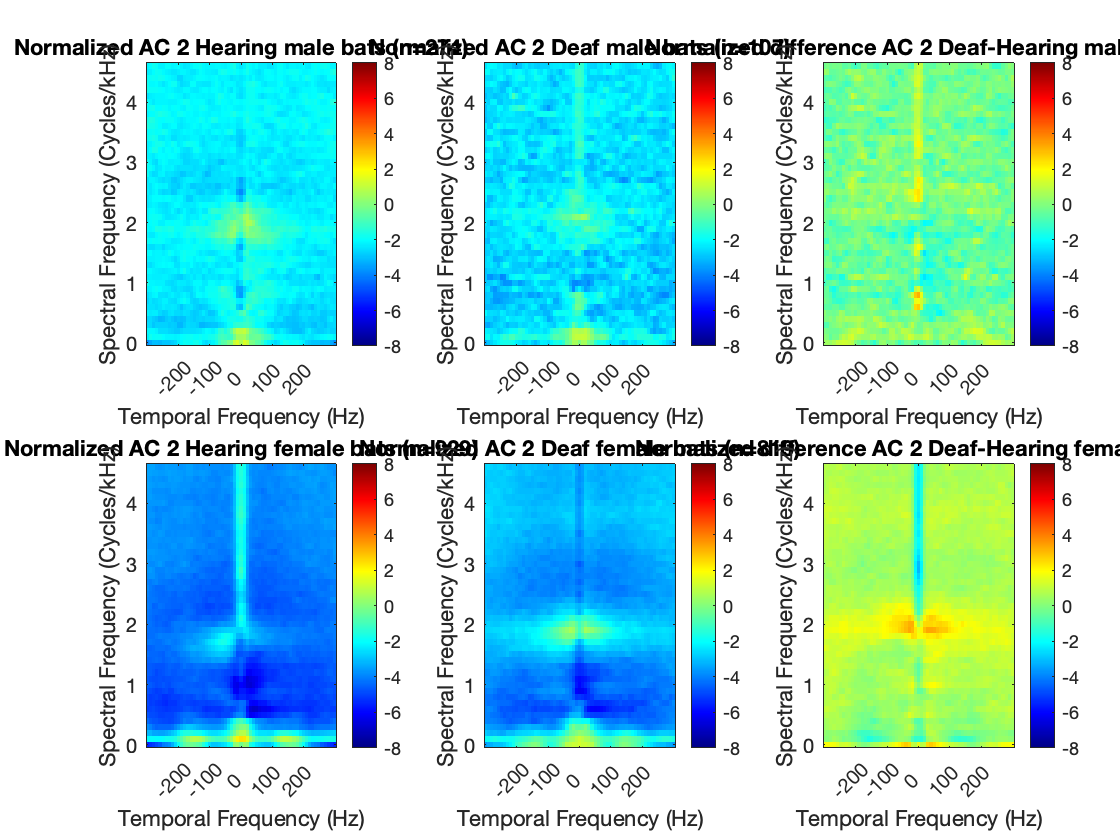

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


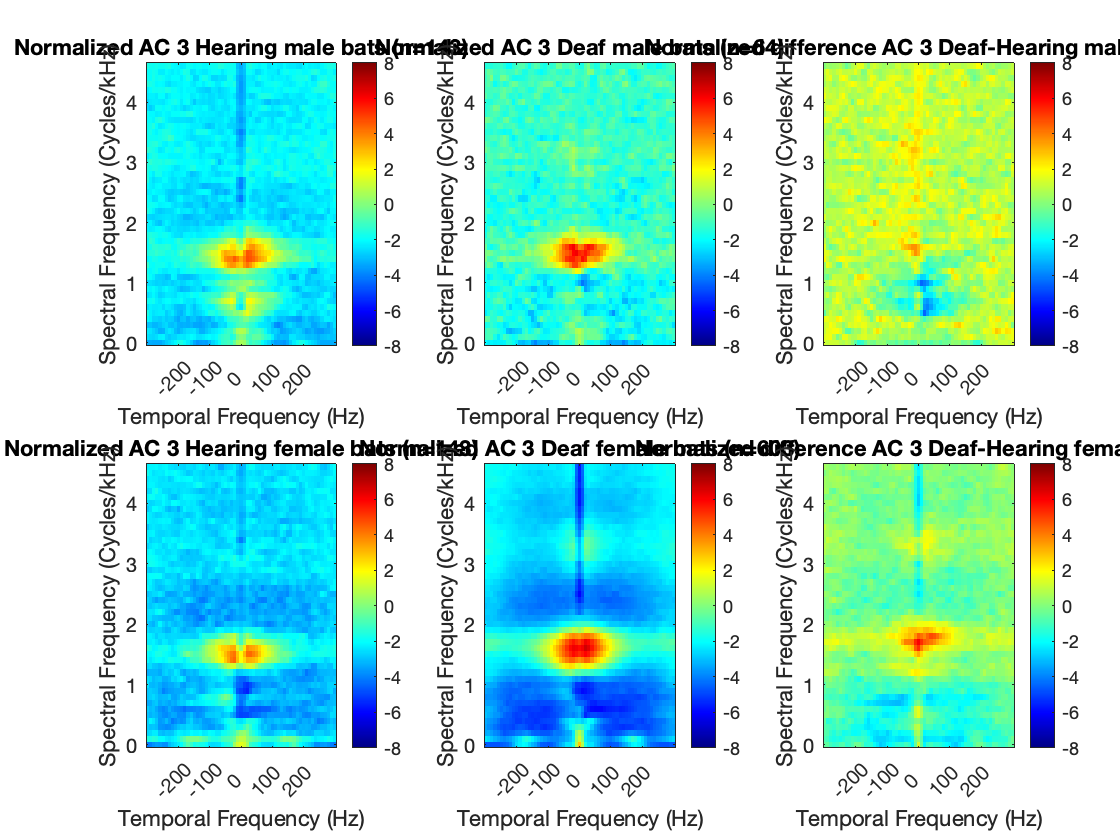

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


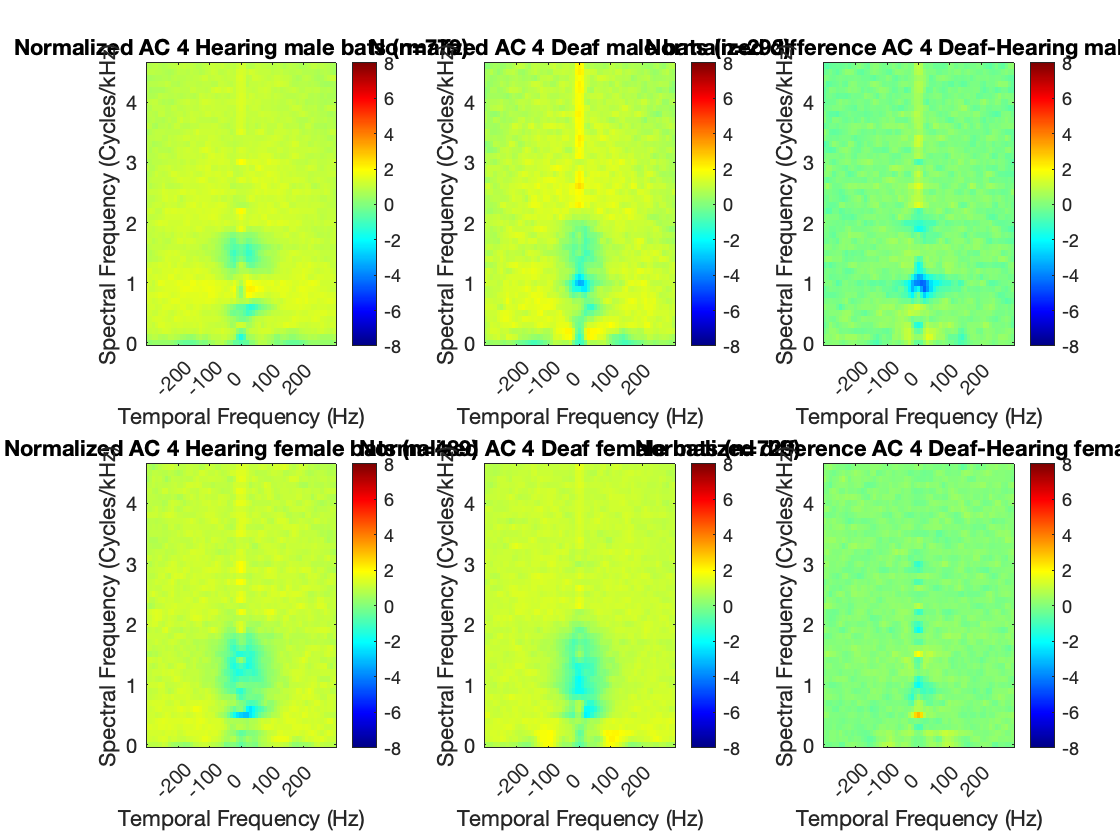

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


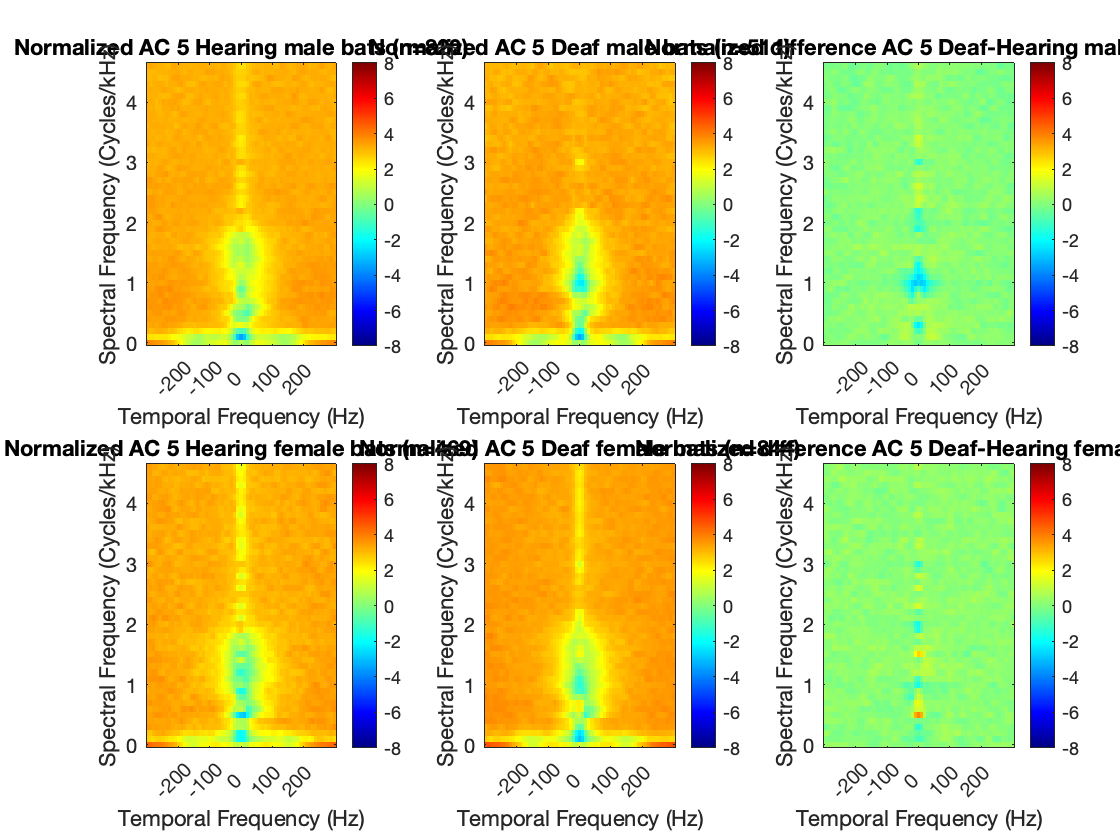

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


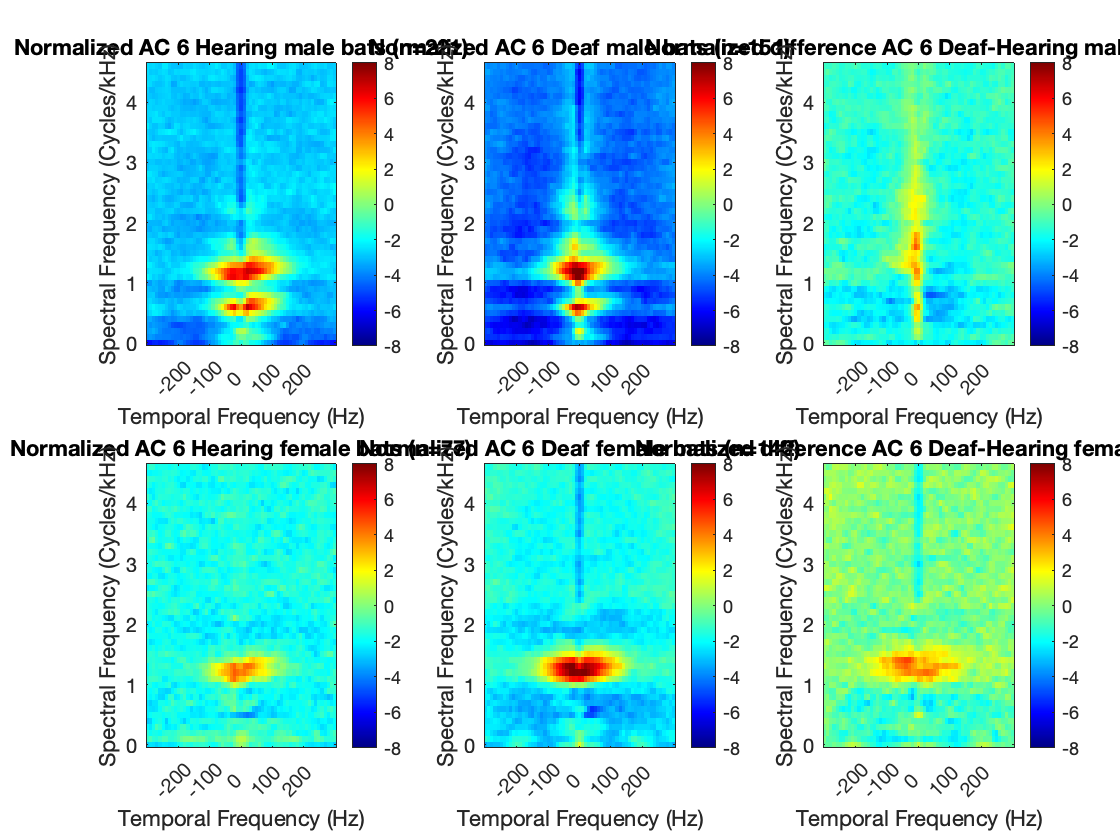

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 7----------------------------


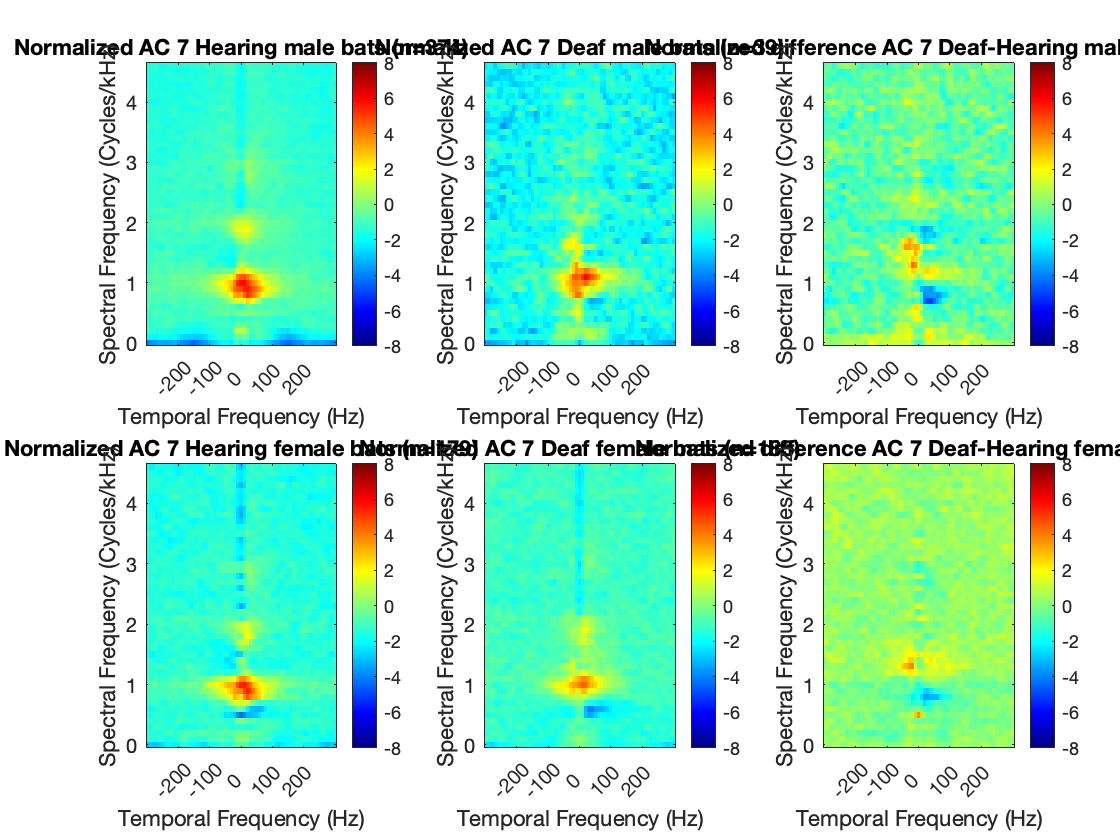

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 8----------------------------


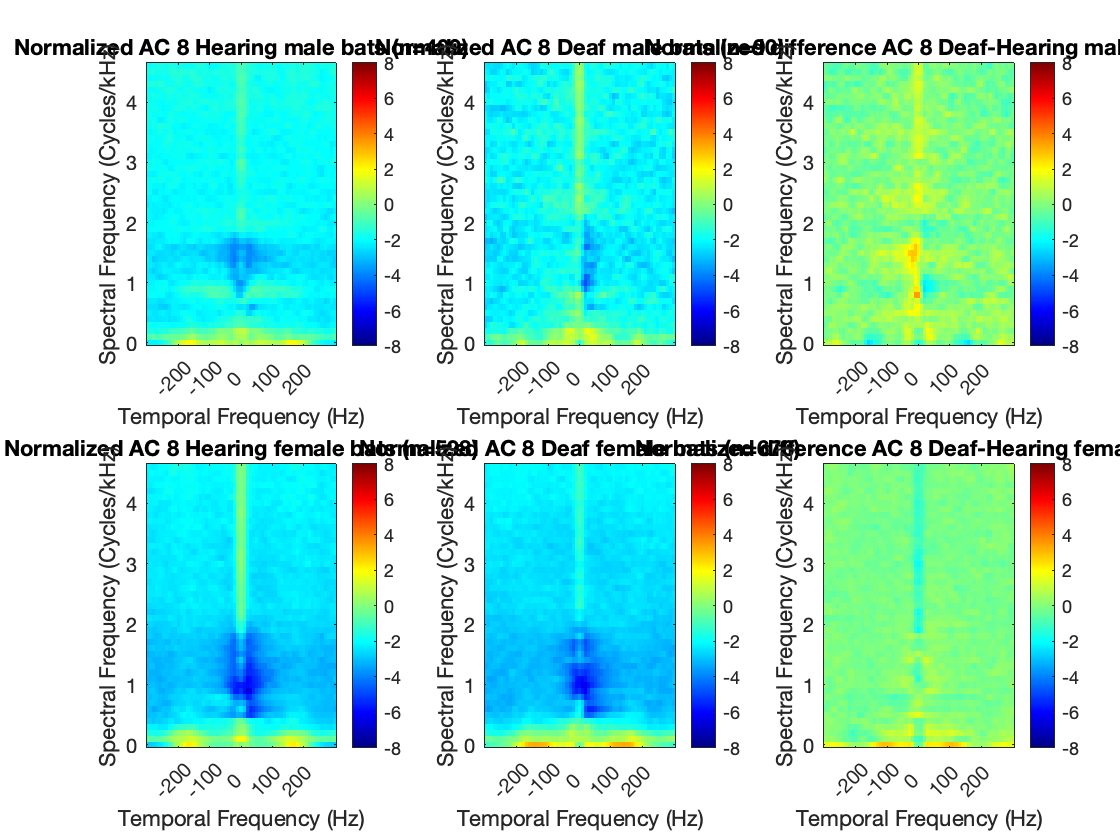

-------------------------------------------------------------------------------


-------------------------------Acoustic Category 9----------------------------


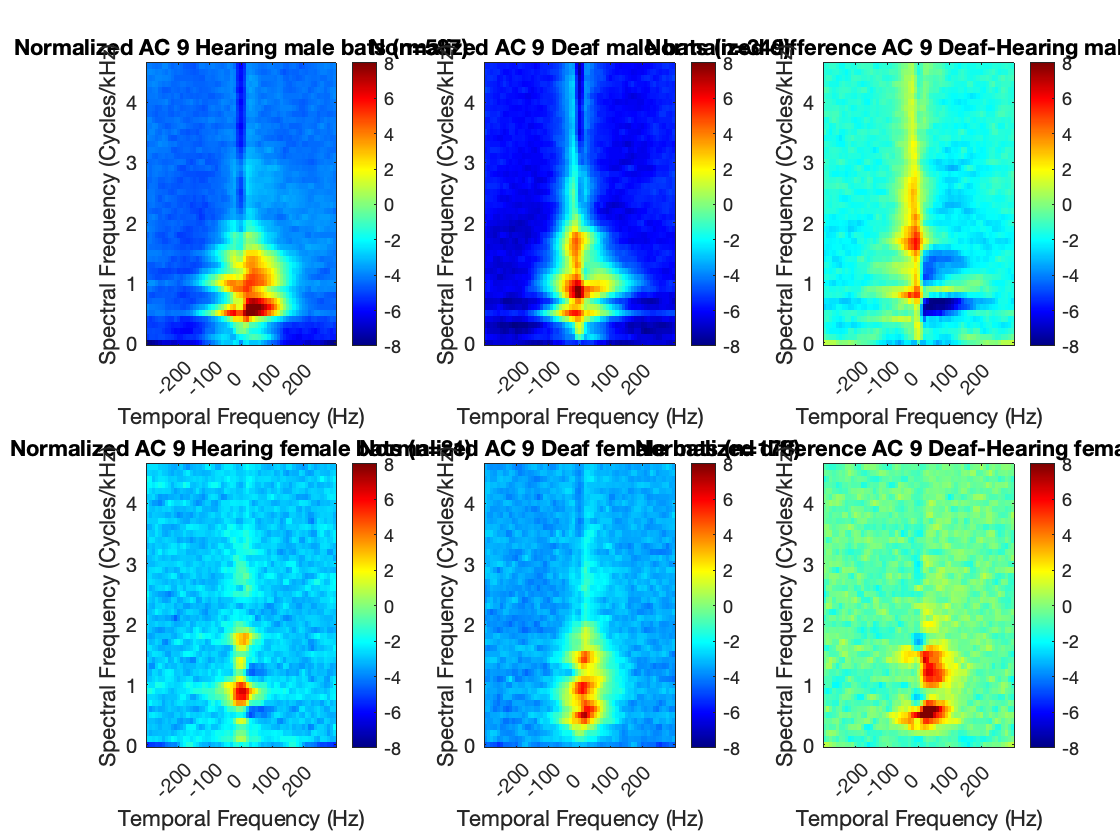

MPS_mean = reshape(mean(MPS)',length(MPS_wf), length(MPS_wt));
for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    figure()
    tiledlayout(2,3)
    nexttile
    IndMH = logical((AcousticClusters==UCat(cc)).*contains(SexDeaf, 'HM')) ;
    MPS_MH = reshape(mean(MPS(IndMH,:))',length(MPS_wf), length(MPS_wt));
    plot_mps(MPS_MH./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
    title(sprintf('Normalized AC %d Hearing male bats (n=%d)', UCat(cc),sum(IndMH)))
    nexttile
    IndMD = logical((AcousticClusters==UCat(cc)).*contains(SexDeaf, 'DM')) ;
    MPS_TrillMD = reshape(mean(MPS(IndMD,:))',length(MPS_wf), length(MPS_wt));
    plot_mps(MPS_TrillMD./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
    title(sprintf('Normalized AC %d Deaf male bats (n=%d)', UCat(cc), sum(IndMD)))
    nexttile
    plot_mps2(MPS_TrillMD./MPS_mean,MPS_MH./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
    title(sprintf('Normalized difference AC %d Deaf-Hearing male bats ',UCat(cc)))
    nexttile
    IndFH = logical((AcousticClusters==UCat(cc)).*contains(SexDeaf, 'HF')) ;
    MPS_FH = reshape(mean(MPS(IndFH,:))',length(MPS_wf), length(MPS_wt));
    plot_mps(MPS_FH./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
    title(sprintf('Normalized AC %d Hearing female bats (n=%d)', UCat(cc),sum(IndFH)))
    nexttile
    IndFD = logical((AcousticClusters==UCat(cc)).*contains(SexDeaf, 'DF')) ;
    MPS_TrillFD = reshape(mean(MPS(IndFD,:))',length(MPS_wf), length(MPS_wt));
    plot_mps(MPS_TrillFD./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
    title(sprintf('Normalized AC %d Deaf female bats (n=%d)', UCat(cc), sum(IndFD)))
    nexttile
    plot_mps2(MPS_TrillFD./MPS_mean,MPS_FH./MPS_mean, MPS_wf, MPS_wt,60,[-8 8]);
    title(sprintf('Normalized difference AC %d Deaf-Hearing female bats ',UCat(cc)))
end

## Run LME only on males

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3     -1554.6    -1541.2    780.31                                 
    lme      4     -1552.7    -1534.9    780.37    0.13123    1          0.71716


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -862.31    -850.48    434.15                                
    lme      4     -861.86    -846.09    434.93    1.5485    1          0.21336


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -416.98    -406.98    211.49                                
    lme      4     -416.11    -402.77    212.05    1.1247    1          0.28892


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3     -2394.3    -2379.4    1200.2                                 
    lme      4     -2392.5    -2372.6    1200.2    0.13485    1          0.71345


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -3001.3    -2985.7    1503.6                                
    lme      4     -3000.6    -2979.9    1504.3    1.3872    1          0.23887


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue    
    lmeR     3     -705.98    -694.23    355.99                                   
    lme      4     -714.96    -699.29    361.48    10.977    1          0.00092244


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             372
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -714.96    -699.29    361.48           -722.96 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF     pValue         Lower       Upper   
    {'(Intercept)'}         0.20563    0.0061596    33.383    370    1.1424e-113     0.19351     0.21774
    {'HorD_D'     }        0.061875     0.009668       6.4    370     4.7054e-10    0.042864    0.080887

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type          

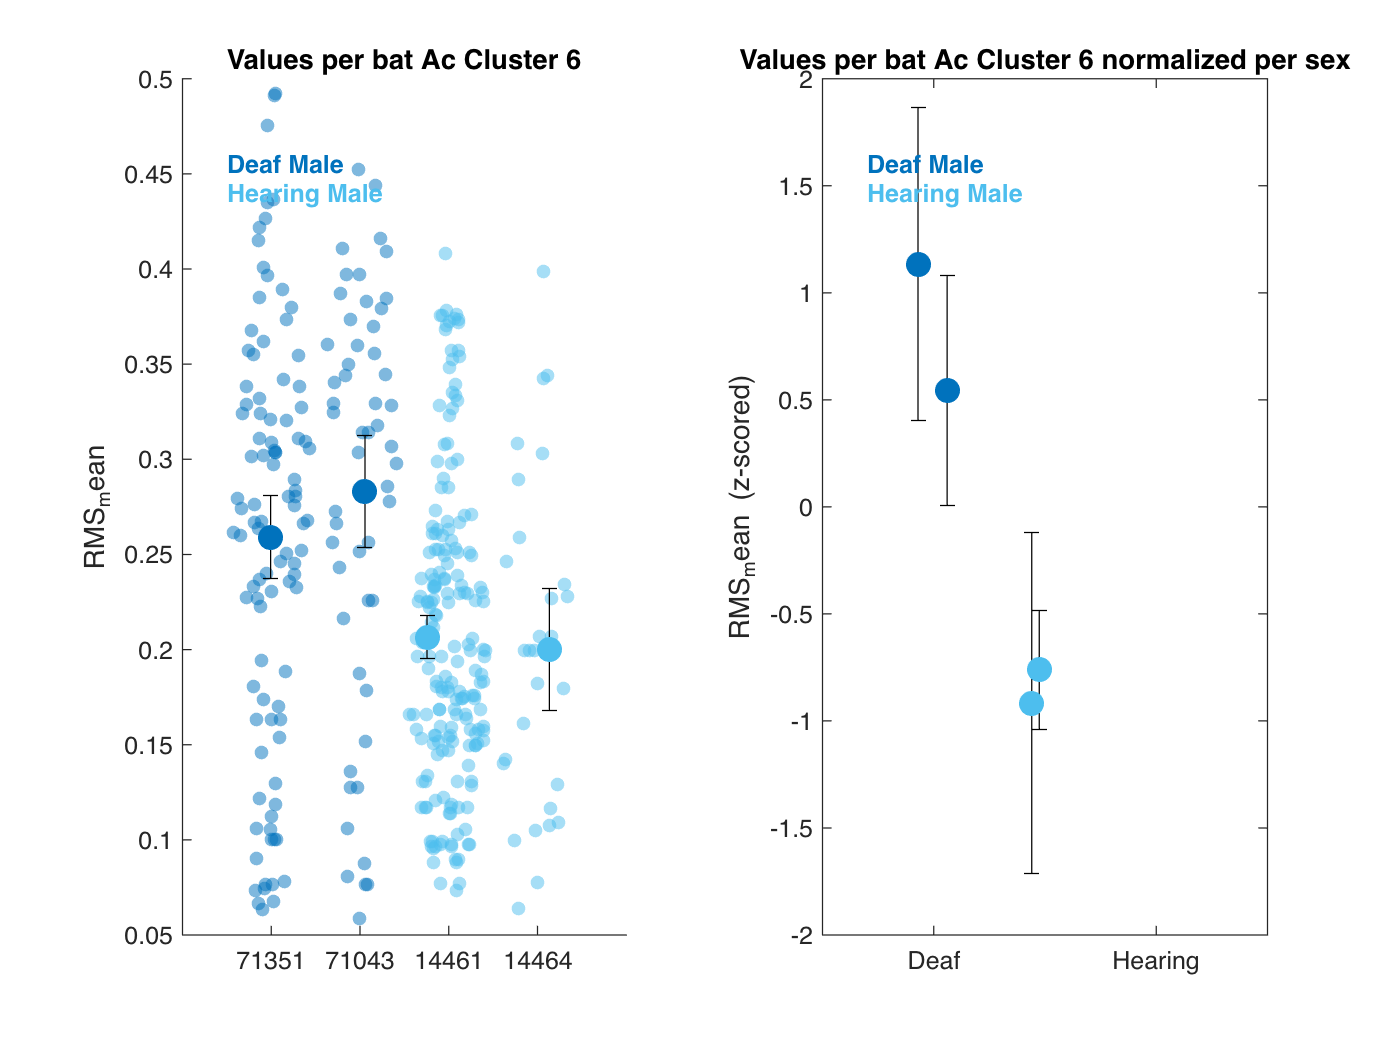

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 7----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -873.06    -860.99    439.53                                
    lme      4     -871.35    -855.26    439.68    0.2951    1          0.58697


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 8----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3     -1336.2    -1323.5    671.09                                 
    lme      4     -1334.7    -1317.8    671.34    0.49985    1          0.47956


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 9----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -1564.5    -1550    785.25                                
    lme      4     -1564.4    -1545    786.19    1.8815    1          0.17016


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


% List of variables that were significant at the previous stage analysis
SigAcVars = logical((Pvalue_matrixFDR(:,1)<0.05) + ((Pvalue_matrixFDR(:,2)<0.05) + (Pvalue_matrixFDR(:,3)<0.05)));
AcVars = Tbl.Properties.VariableNames(6:end);
AcVars = AcVars(SigAcVars);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix_Post_hoc_male = nan(length(AcVars),length(UCat));


for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    for vv=1:length(AcVars)
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
        AcVar = Tbl.(sprintf('%s',AcVars{vv}));
        if contains(AcVars{vv}, 'Mic')
            Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*contains(Sex, 'M'));
            Tbl_local = table(BatID(Ind), CallType(Ind), AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','AcousticClusters','HorD', 'AcVar'});
        else
            Ind = logical(AcousticClusters==UCat(cc).*contains(Sex, 'M'));
            Tbl_local = table(BatID(Ind), CallType(Ind), AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT', 'AcousticClusters','HorD', 'AcVar'});
        end
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

        % Full Model
        lme = fitlme(Tbl_local, 'AcVar ~ HorD + (1|BatID)');
        % Reduced model without deafening fixed effect
        lmeR = fitlme(Tbl_local, 'AcVar ~ 1+ (1|BatID)');
        TestLME_HD=compare(lmeR, lme)

        Pvalue_matrix_Post_hoc_male(vv,cc) = TestLME_HD.pValue(2);
        if TestLME_HD.pValue(2)<0.05
            lme

            % Nice plot
            AcVar_mean_pBat = nan(4,1);
            AcVar_se_pBat = nan(4,1);
            Col_local = nan(4,3);
            figure()
            tiledlayout(1,2)
            nexttile
            for bb=1:4
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb+6))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb+6))));
                end
                AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
                AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb+6}),:);
                hold on
                swarmchart(bb*ones(sum(Ind),1),AcVar(Ind),30,Col_local(bb,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            end

            AcVar_Male_meanse(1) = mean(AcVar_mean_pBat);
            AcVar_Male_meanse(2) = std(AcVar_mean_pBat);
            AcVar_meanse_pBat_sexnorm = nan(length(AcVar_mean_pBat),2);
            for bb=1:4
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb+6))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb+6))));
                end
                AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan');
                AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;

            end
            XHorD = (1:sum(contains(BatSexDeaf, 'Male'))) + (rand(sum(contains(BatSexDeaf, 'Male')),1)'-0.5)*0.5;
            hold on
            errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.')
            hold on
            scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
            ylabel(sprintf('%s', AcVars{vv}));
            YLim = get(gca, 'YLim');
            XLim = get(gca, 'XLim');
            for ct=1:2
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', 1:4,'XTickLabel', BatName(7:end))
            hold off
            title(sprintf('Values per bat Ac Cluster %d', UCat(cc)))


            nexttile
            XHorD = ([1 1 2 2]) + (rand(4,1)'-0.5)*0.5;
            errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
            hold on
            scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
            ylabel(sprintf('%s (z-scored)', AcVars{vv}))
            XLim = [0 4];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=1:2
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))

        end
    end
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
end

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

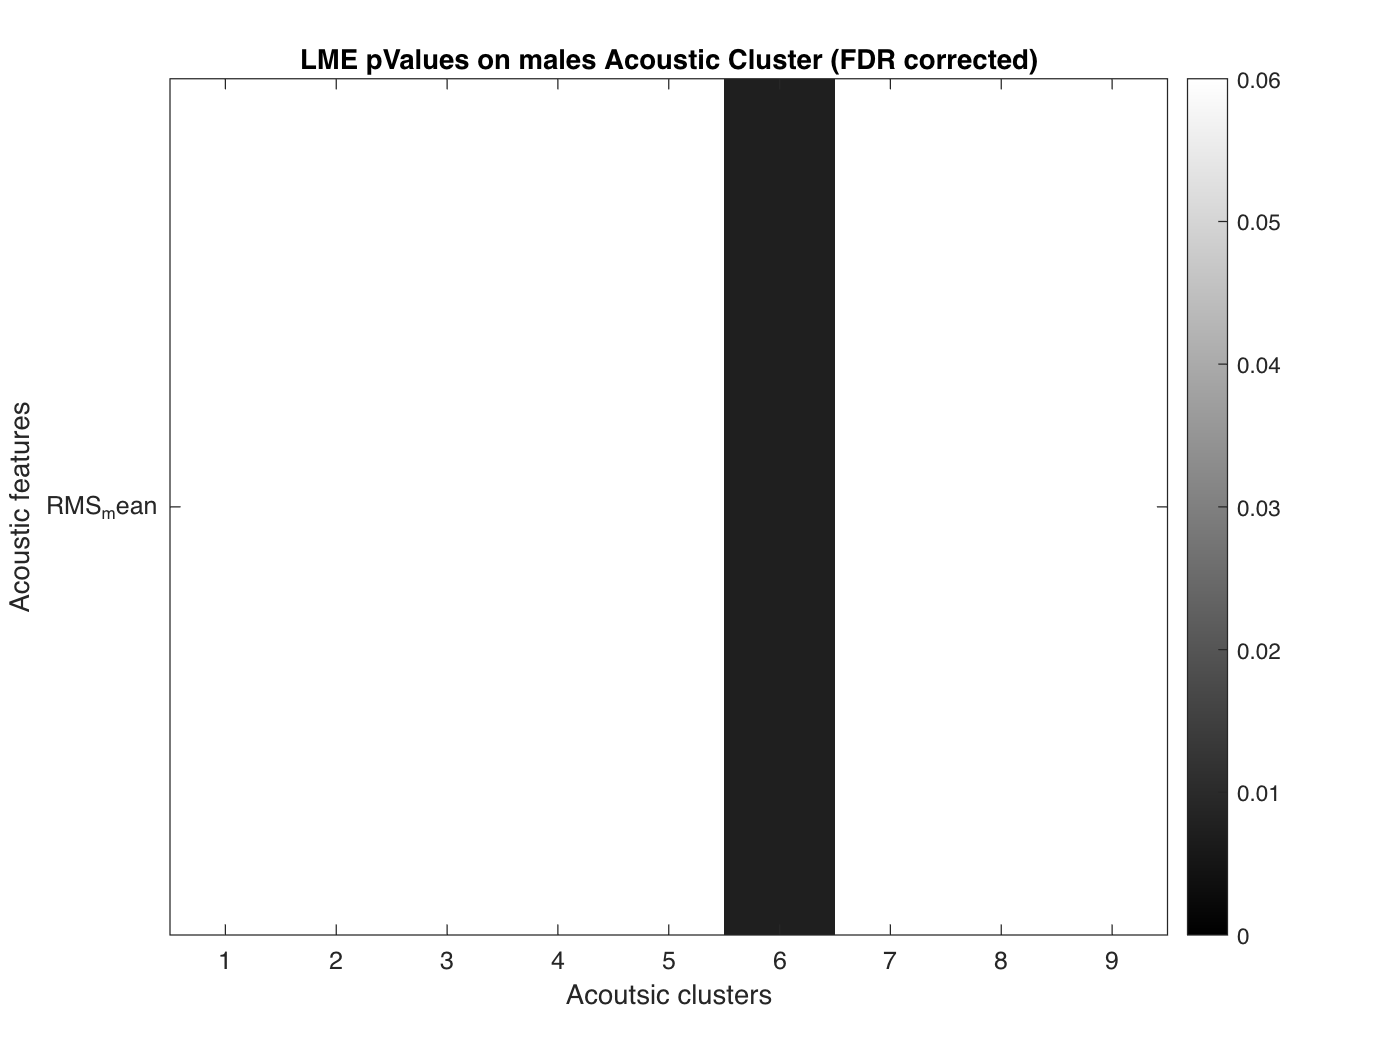

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = reshape(Pvalue_matrix_Post_hoc_male,numel(Pvalue_matrix_Post_hoc_male),1);
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);

Pvalue_matrix_Post_hoc_maleFDR = reshape(Pvalue_vectorFDR, size(Pvalue_matrix_Post_hoc_male));


figure()
Im = imagesc(Pvalue_matrix_Post_hoc_maleFDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
ylabel('Acoustic features')
xlabel('Acoutsic clusters')
title(sprintf('LME pValues on males Acoustic Cluster (FDR corrected)'))

## Run LME only on females

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 1----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue
    lmeR     3     -2781.8    -2767.3    1393.9                                
    lme      4     -2770.2    -2750.8    1389.1    -9.5927    1          1     


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 2----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -5402.8    -5386.4    2704.4                                  
    lme      4     -5410.4    -5388.5    2709.2    9.6063    1          0.0019391


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1748
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -5410.4    -5388.5    2709.2           -5418.4 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue       Lower       Upper   
    {'(Intercept)'}        0.090637    0.0016852    53.785    1746            0    0.087332    0.093942
    {'HorD_D'     }        0.019975    0.0024619    8.1134    1746    9.187e-16    0.015146    0.024803

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Es

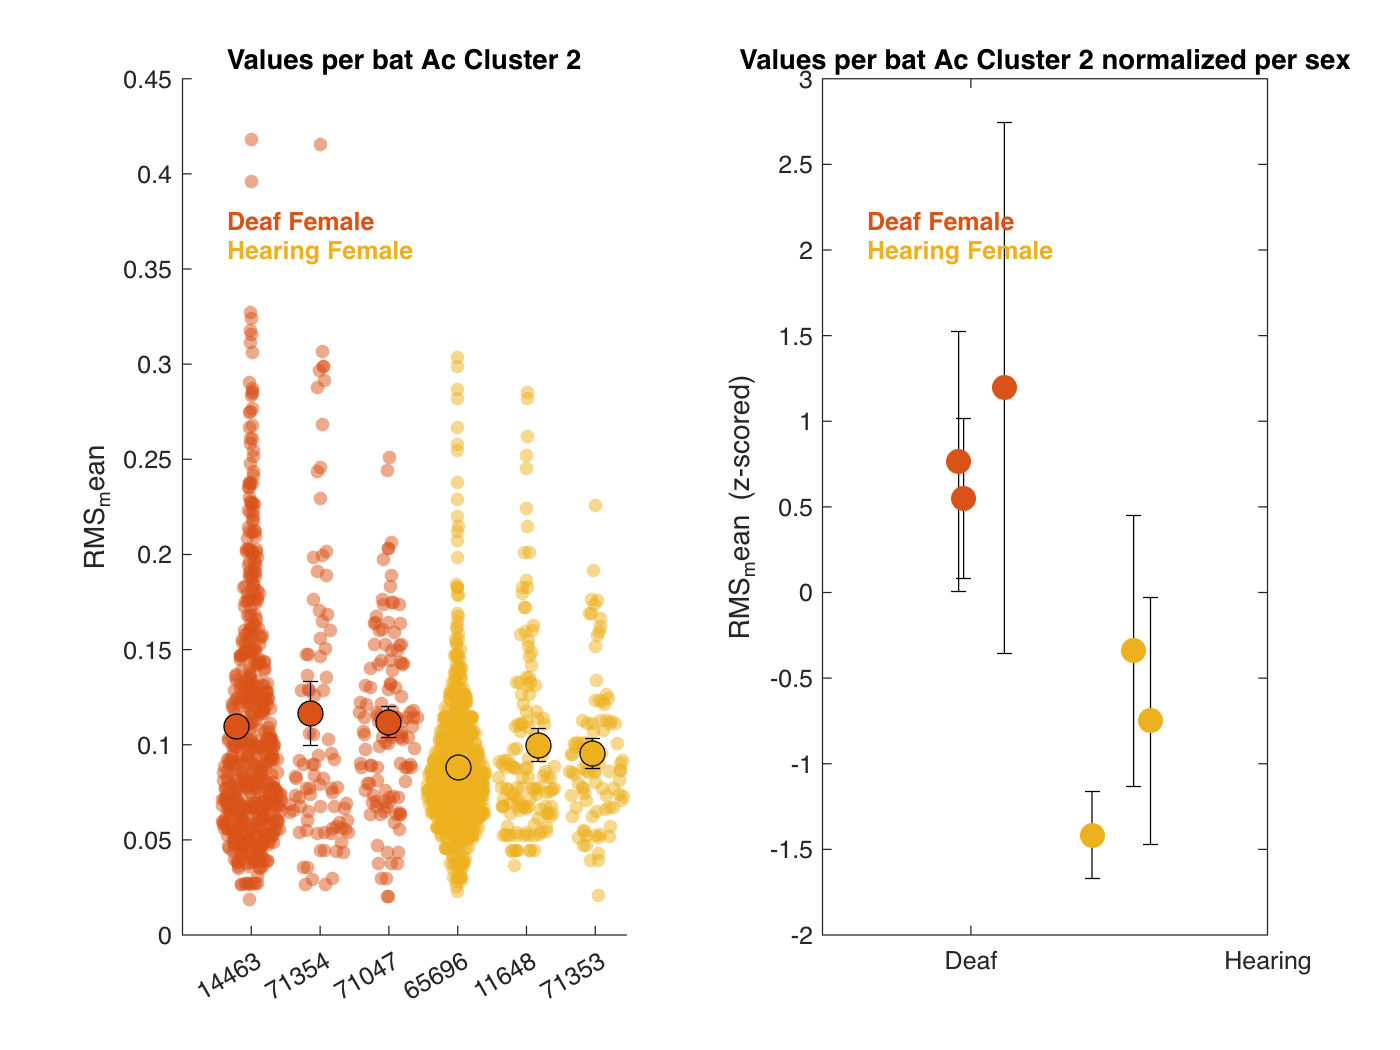

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 3----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC        LogLik    LRStat    deltaDF    pValue  
    lmeR     3     -2105    -2091.2    1055.5                                 
    lme      4     -2107    -2088.6    1057.5    4.0144    1          0.045113


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             746
    Fixed effects coefficients           2
    Random effects coefficients          6
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC        LogLikelihood    Deviance
    -2107    -2088.6    1057.5           -2115   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF     pValue       Lower        Upper   
    {'(Intercept)'}         0.10413    0.0077479     13.44    744    5.053e-37      0.08892     0.11934
    {'HorD_D'     }        0.023933     0.010168    2.3538    744      0.01884    0.0039723    0.043893

Random effects covariance parameters (95% CIs):
Group: BatID (6 Levels)
    Name1                  Name2                  Type           Estima

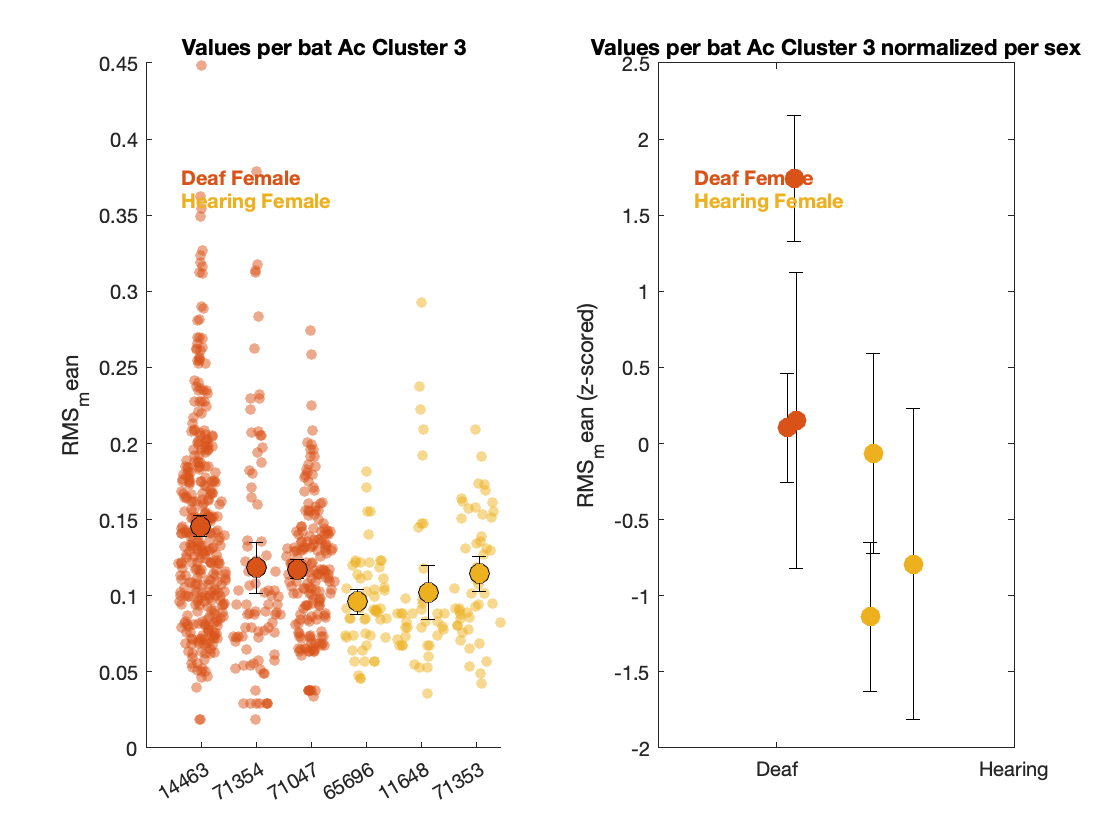

-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 4----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3     -2921.8    -2906.5    1463.9                                 
    lme      4     -2920.6    -2900.1    1464.3    0.74931    1          0.38669


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 5----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -2749.2    -2733.6    1377.6                                
    lme      4     -2748.3    -2727.6    1378.1    1.1079    1          0.29255


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 6----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -540.24    -530.08    273.12                                
    lme      4     -539.67    -526.11    273.83    1.4249    1          0.23259


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 7----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3     -820.94    -809.25    413.47                                 
    lme      4     -819.35    -803.76    413.67    0.41029    1          0.52182


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 8----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3       -4301    -4285.5    2153.5                                
    lme      4     -4300.1    -4279.5    2154.1    1.1262    1          0.28859


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


-------------------------------Acoustic Category 9----------------------------


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


*********************     LMEs on RMS_mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lmeR     3     -369.51    -358.84    187.75                                
    lme      4     -369.43     -355.2    188.72    1.9229    1          0.16553


-------------------------------------------------------------------------------


-------------------------------------------------------------------------------


% List of variables that were significant at the previous stage analysis
SigAcVars = logical((Pvalue_matrixFDR(:,1)<0.05) + ((Pvalue_matrixFDR(:,2)<0.05) + (Pvalue_matrixFDR(:,3)<0.05)));
AcVars = Tbl.Properties.VariableNames(6:end);
AcVars = AcVars(SigAcVars);

% All P-value of the tests are saved here for FDR correction in the end
Pvalue_matrix_Post_hoc_female = nan(length(AcVars),length(UCat));


for cc=1:length(UCat)
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------Acoustic Category %d----------------------------\n', UCat(cc))
    for vv=1:length(AcVars)
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1,'-------------------------------------------------------------------------------\n')
        fprintf(1, '*********************     LMEs on %s   ********************\n', AcVars{vv})
        AcVar = Tbl.(sprintf('%s',AcVars{vv}));
        if contains(AcVars{vv}, 'Mic')
            Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*contains(Sex, 'F'));
            Tbl_local = table(BatID(Ind), CallType(Ind), AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT','AcousticClusters','HorD', 'AcVar'});
        else
            Ind = logical(AcousticClusters==UCat(cc).*contains(Sex, 'F'));
            Tbl_local = table(BatID(Ind), CallType(Ind), AcousticClusters(Ind),Deaf(Ind), AcVar(Ind), 'VariableNames', {'BatID', 'CT', 'AcousticClusters','HorD', 'AcVar'});
        end
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

        % Full Model
        lme = fitlme(Tbl_local, 'AcVar ~ HorD + (1|BatID)');
        % Reduced model without deafening fixed effect
        lmeR = fitlme(Tbl_local, 'AcVar ~ 1+ (1|BatID)');
        TestLME_HD=compare(lmeR, lme)

        Pvalue_matrix_Post_hoc_female(vv,cc) = TestLME_HD.pValue(2);
        if TestLME_HD.pValue(2)<0.05
            lme

            % Nice plot
            AcVar_mean_pBat = nan(6,1);
            AcVar_se_pBat = nan(6,1);
            Col_local = nan(6,3);
            figure()
            tiledlayout(1,2)
            nexttile
            for bb=1:6
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
                AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
                Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
                hold on
                swarmchart(bb*ones(sum(Ind),1),AcVar(Ind),30,Col_local(bb,:),'o','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
            end

            AcVar_feMale_meanse(1) = mean(AcVar_mean_pBat);
            AcVar_feMale_meanse(2) = std(AcVar_mean_pBat);
            AcVar_meanse_pBat_sexnorm = nan(length(AcVar_mean_pBat),2);
            for bb=1:6
                if contains(AcVars{vv}, 'Mic')
                    Ind = logical(MicAudioGood01.*(AcousticClusters==UCat(cc)).*strcmp(BatID,num2str(BatName(bb))));
                else
                    Ind = logical(AcousticClusters==UCat(cc) .* strcmp(BatID,num2str(BatName(bb))));
                end
                AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_feMale_meanse(1))./AcVar_feMale_meanse(2), 'omitnan');
                AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_feMale_meanse(1))./AcVar_feMale_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;

            end
            XHorD = (1:sum(contains(BatSexDeaf, 'Female'))) + (rand(sum(contains(BatSexDeaf, 'Female')),1)'-0.5)*0.5;
            hold on
            errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.')
            hold on
            scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled', 'MarkerEdgeColor', 'k')
            ylabel(sprintf('%s', AcVars{vv}));
            YLim = get(gca, 'YLim');
            XLim = get(gca, 'XLim');
            for ct=3:4
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca, 'XTick', 1:6,'XTickLabel', BatName(1:6))
            hold off
            title(sprintf('Values per bat Ac Cluster %d', UCat(cc)))


            nexttile
            XHorD = ([1 1 1 2 2 2]) + (rand(6,1)'-0.5)*0.5;
            errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
            hold on
            scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
            ylabel(sprintf('%s (z-scored)', AcVars{vv}))
            XLim = [0 3];
            set(gca, 'XLim', XLim);
            YLim = get(gca, 'YLim');
            for ct=3:4
                text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
            end
            set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
            hold off
            title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))

        end
    end
    fprintf(1,'-------------------------------------------------------------------------------\n')
    fprintf(1,'-------------------------------------------------------------------------------\n')
end

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

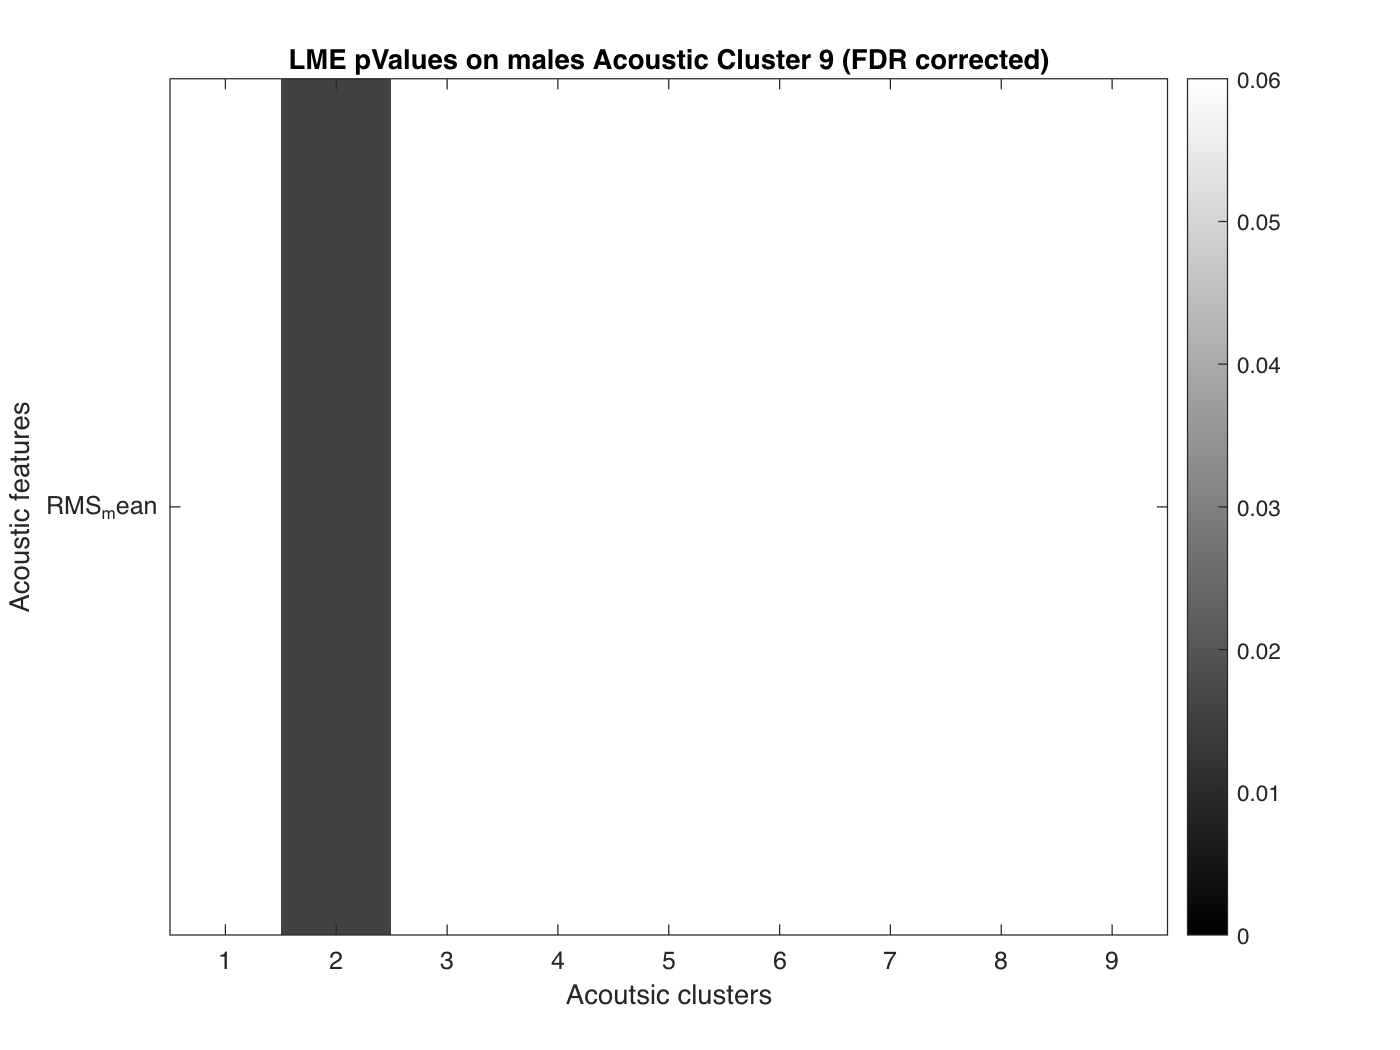

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
Pvalue_vector = reshape(Pvalue_matrix_Post_hoc_female,numel(Pvalue_matrix_Post_hoc_female),1);
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);

Pvalue_matrix_Post_hoc_femaleFDR = reshape(Pvalue_vectorFDR, size(Pvalue_matrix_Post_hoc_female));


figure()
Im = imagesc(Pvalue_matrix_Post_hoc_femaleFDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
ylabel('Acoustic features')
xlabel('Acoutsic clusters')
title(sprintf('LME pValues on males Acoustic Cluster %d (FDR corrected)',cc))

## Bootstrap for the significance

Let's run the same analysis as before but shuffle the deafening labels accross bats

load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'), 'Pvalue_matrixFDR_rand','Pvalue_CellFDR_randInd','NCK')

NBoot = 200;
if ~exist('NCK','var')
    % List of variables
    AcVars = Tbl.Properties.VariableNames(6:end);
    NCK = perms(1:10);
    for bb=1:size(NCK,1)
        if prod(NCK(bb,:)==(1:10))
            NCK(bb,:)=[];
            break
        end
    end
    NCK = NCK(randperm(size(NCK,1)),:);% randomized permutations to increase diversity in the selected ones
end

% All P-value of the tests are saved here for FDR correction in the end

Pvalue_CellFDR_rand = cell(length(NBoot),1);
if exist('Pvalue_CellFDR_randInd','var')
    Startbb = size(Pvalue_CellFDR_randInd,1);
    Pvalue_CellFDR_randInd = [Pvalue_CellFDR_randInd; cell(length(NBoot),1)];
else
    Startbb=0;
    Pvalue_CellFDR_randInd = cell(length(NBoot),1);
end
parfor bb=1:NBoot
    Pvalue_matrix_rand = nan(length(AcVars),4);
    if ~rem(bb,20)
        fprintf(1, '\n\n*********************     Permutation %d/%d   ********************\n', bb, NBoot)
    end
    % Get the randomized vector ready for Deafness
    BatSexDeaf_rand = BatSexDeaf(NCK(Startbb+bb,:));
    Pvalue_CellFDR_randInd{Startbb+bb} = NCK(Startbb+bb,:);
    Deaf_rand = cell(length(BatID),1);
    for bat = 1:length(BatName)
        if contains(BatSexDeaf_rand{bat}, 'Deaf')
            Deaf_rand(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        elseif contains(BatSexDeaf_rand{bat}, 'Hearing')
            Deaf_rand(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        else
            keyboard
        end
    end
    
    % Run the model with the 3 predictors
    % List of variables
    for vv=1:length(AcVars)
        if vv==1 && ~rem(bb,20)
            fprintf(1, ' LMEs on %s, ', AcVars{vv})
        elseif ~rem(bb,1)
            fprintf(1, '%s, ', AcVars{vv})
        end
        AcVar = Tbl.(sprintf('%s',AcVars{vv}));
        if contains(AcVars{vv}, 'Mic')
            Tbl_local = table(BatID(MicAudioGood01), CallType(MicAudioGood01), Sex(MicAudioGood01),AcousticClusters(MicAudioGood01),Deaf_rand(MicAudioGood01), AcVar(MicAudioGood01), 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        else
            Tbl_local = table(BatID, CallType, Sex,AcousticClusters,Deaf_rand, AcVar, 'VariableNames', {'BatID', 'CT','Sex','AcousticClusters','HorD', 'AcVar'});
        end
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
        Tbl_local.AcousticClusters = categorical(Tbl_local.AcousticClusters);
        Tbl_local.Sex = categorical(Tbl_local.Sex);
        Tbl_local.BatID = categorical(Tbl_local.BatID);
    
        % Full Model
        try
            lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD * AcousticClusters+ (AcousticClusters|BatID)');
            % Reduced model without deafening fixed effect
            lmeR = fitlme(Tbl_local, 'AcVar ~ Sex * AcousticClusters + (AcousticClusters|BatID)');
            TestLME_HD=compare(lmeR, lme);
        
            Pvalue_matrix_rand(vv,1) = TestLME_HD.pValue(2);
            if TestLME_HD.pValue(2)<0.05
                lme;
                lme2 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + HorD * AcousticClusters + (AcousticClusters|BatID)');
                TestLME_Int3=compare(lme2, lme);
                Pvalue_matrix_rand(vv,2) = TestLME_Int3.pValue(2);
                lme3 = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + AcousticClusters + (AcousticClusters|BatID)');
                TestLME_Int_HorD_AcCluster=compare(lme3, lme2);
                Pvalue_matrix_rand(vv,3) = TestLME_Int_HorD_AcCluster.pValue(2);
                lme4 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD * AcousticClusters + (AcousticClusters|BatID)');
                TestLME_Int_HorD_Sex=compare(lme4, lme2);
                Pvalue_matrix_rand(vv,4) = TestLME_Int_HorD_Sex.pValue(2);
            end
        catch
            fprintf(1,'error with sequence:')
            NCK(Startbb+bb,:)
            break
        end

    end
    % Now correct that probability for False discovery rate (True proba =
    % p*(Num_comparisons-rank))
    Pvalue_vector = [Pvalue_matrix_rand(:,1);Pvalue_matrix_rand(:,2);Pvalue_matrix_rand(:,3);Pvalue_matrix_rand(:,4)];
    NonNaNInd = ~isnan(Pvalue_vector);
    [~,Ord]=sort(Pvalue_vector(NonNaNInd));
    Ord(Ord==length(Ord)) = length(Ord)-1;
    Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
    Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
    Pvalue_CellFDR_rand{bb} = [Pvalue_vectorFDR(1:size(Pvalue_matrix_rand,1)) Pvalue_vectorFDR((size(Pvalue_matrix_rand,1)+1) : 2*size(Pvalue_matrix_rand,1)) Pvalue_vectorFDR((2*size(Pvalue_matrix_rand,1)+1) : 3*size(Pvalue_matrix_rand,1)) Pvalue_vectorFDR((3*size(Pvalue_matrix_rand,1)+1) : end)];
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
Duration, RMS_mean, Sal_mean, F0_mean, Spect_mean, Spect_std, Spect_kurt, Spect_skew, Spect_ent, Time_mean, Time_std, Time_kurt, Time_skew, Time_ent, SpectralMean_mean, Q1_mean, Q2_mean, Q3_mean, SpectMic_mean, SpectMic_std, SpectMic_kurt, SpectMic_skew, SpectMic_ent, Q1Mic_mean, Q2Mic_mean, Q3Mic_mean, Duration, RMS_mean, Sal_mean, F0_mean, Spect_mean, 

if exist('Pvalue_matrixFDR_rand', 'var')
    Pvalue_matrixFDR_rand = cat(3,Pvalue_matrixFDR_rand,nan(length(AcVars),4, NBoot))
else
    Pvalue_matrixFDR_rand = nan(length(AcVars),4, NBoot);
end
for bb=1:NBoot
    Pvalue_matrixFDR_rand(:,:,Startbb+bb) = Pvalue_CellFDR_rand{bb};
end
save(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls.mat'), 'Pvalue_matrixFDR_rand','Pvalue_CellFDR_randInd','NCK','-append')

**Now plot the probability of random discovery**

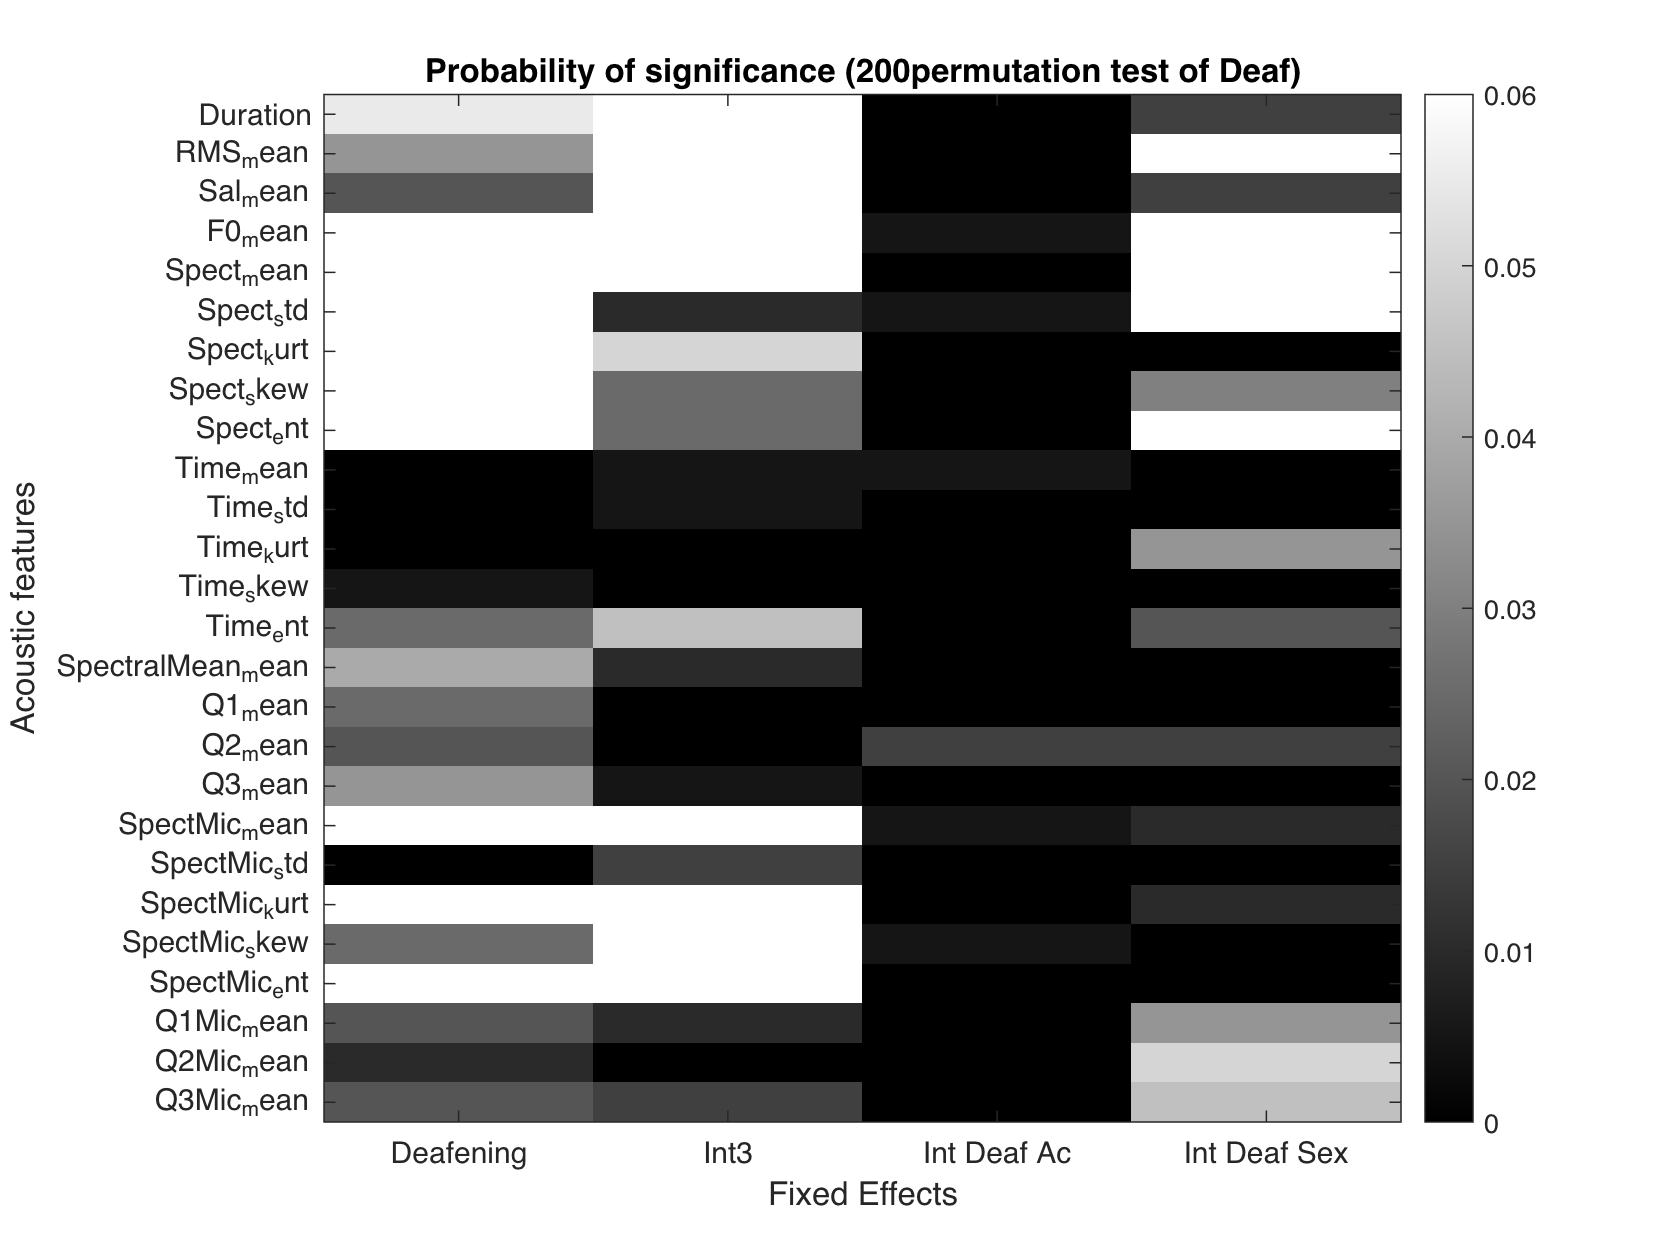

figure()

Im = imagesc(sum(Pvalue_matrixFDR_rand<0.01,3)./NBoot);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1:4,'XTickLabel', {'Deafening' 'Int3' 'Int Deaf Ac' 'Int Deaf Sex'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title(sprintf('Probability of significance (%dpermutation test of Deaf)', NBoot))


    % run the models within each acoustic category with Sex and Deaf


function [MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<6
        Log=1;
    end

    if nargin<7
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<8
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<5
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    colorbar()
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_local*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end


function [MPS4plot, Wt_local, Wf_local]=plot_mps2(MPS1,MPS2, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
    if nargin<5
        DBNOISE=60;
    end

    if nargin<7
        Log=1;
    end

    if nargin<8
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<9
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<6
        CLim = nan;
    end
    if nargin<10
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS1 = MPS1(Wf_i, Wt_i);
    MPS2 = MPS2(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS1)-10*log10(MPS2);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS1-MPS2; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    axis xy
    colormap(Im.Parent,'jet');
    colorbar()
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(floor(Wt_local*10^-2))*10^2;
    XTickLabel = -MaxWt:100:MaxWt;
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end